[https://github.com/Mamtapriya/Linear-Regression-of-data-driven-battery](https://github.com/Mamtapriya/Linear-Regression-of-data-driven-battery)

[https://github.com/Ronakj2904/BatteryManagementSystem_Algorithm_usingMatlab/tree/master/State_Of_Charge](https://github.com/Ronakj2904/BatteryManagementSystem_Algorithm_usingMatlab/tree/master/State_Of_Charge)

[https://github.com/jollylst/MoBike_LifeCyclePrediction/blob/master/MoBike%20V1.0.ipynb](https://github.com/jollylst/MoBike_LifeCyclePrediction/blob/master/MoBike%20V1.0.ipynb)

[https://github.com/er-sourav99/Forest_Fires_Dataset_Analysis_and_prediction/blob/master/Forest_Fires_Prediction.ipynb](https://github.com/er-sourav99/Forest_Fires_Dataset_Analysis_and_prediction/blob/master/Forest_Fires_Prediction.ipynb)

[https://github.com/jhagyanesh/Telecom-Churn-Prediction/blob/master/Gyanesh_Jha_Telecom-Churn.ipynb](https://github.com/jhagyanesh/Telecom-Churn-Prediction/blob/master/Gyanesh_Jha_Telecom-Churn.ipynb)

[https://github.com/Mamtapriya/Linear-Regression-of-data-driven-battery](https://github.com/Mamtapriya/Linear-Regression-of-data-driven-battery)

[https://github.com/Mamtapriya/Linear-Regression-of-data-driven-battery/blob/main/Batch1_Linear_Regression.ipynb](https://github.com/Mamtapriya/Linear-Regression-of-data-driven-battery/blob/main/Batch1_Linear_Regression.ipynb)

[https://github.com/Mamtapriya/Linear-Regression-of-data-driven-battery/blob/main/Load_Data_Linear_Regression.ipynb](https://github.com/Mamtapriya/Linear-Regression-of-data-driven-battery/blob/main/Load_Data_Linear_Regression.ipynb)

[https://github.com/lanmei1211/Battery_Cycle_Life_Prediction_Pytorch/blob/a5c4705111feb14a8739595c50be4cac0eca3157/data_preprocessing.py#L112](https://github.com/lanmei1211/Battery_Cycle_Life_Prediction_Pytorch/blob/a5c4705111feb14a8739595c50be4cac0eca3157/data_preprocessing.py#L112)

# 데이타 읽어 들이기.

%['ap:/nobackup/_phd_work/_battery_soh/_dataset/data.matr.io/2017-05-12_batchdata_updated_struct_errorcorrect.mat',
%           'C:/nobackup/_phd_work/_battery_soh/_dataset/data.matr.io/2017-06-30_batchdata_updated_struct_errorcorrect.mat',
%           'C:/nobackup/_phd_work/_battery_soh/_dataset/data.matr.io/2018-04-12_batchdata_updated_struct_errorcorrect.mat']

clear ;
close all;

batchNum = 1;
load C:\nobackup\_phd_work\_battery_soh\_dataset\data.matr.io\2017-05-12_batchdata_updated_struct_errorcorrect.mat
trainData = batch;
clear batch
clear batch_date

load C:\nobackup\_phd_work\_battery_soh\_dataset\data.matr.io\2017-06-30_batchdata_updated_struct_errorcorrect.mat
trainData2 = batch;
clear batch
clear batch_date

load C:\nobackup\_phd_work\_battery_soh\_dataset\data.matr.io\2018-04-12_batchdata_updated_struct_errorcorrect.mat
trainData3 = batch;
clear batch
clear batch_date

ryan4_battery_dataset_raw_org_sample1 = trainData(1);
ryan4_battery_dataset_raw_org_sample2 = trainData(2);
ryan4_battery_dataset_raw_org_sample3 = trainData(3);

save('ryan4_battery_dataset_raw_org_sample1.mat','ryan4_battery_dataset_raw_org_sample1' )
save('ryan4_battery_dataset_raw_org_sample2.mat','ryan4_battery_dataset_raw_org_sample2' )
save('ryan4_battery_dataset_raw_org_sample3.mat','ryan4_battery_dataset_raw_org_sample3' )


new_index = 1;
ryan4_battery_dataset_raw = zeros();
% 이 코드가 중요함. ryan4_battery_dataset_raw 이 structure를 가짐을 알려주어야 함.
ryan4_battery_dataset_raw = ryan4_extract_feature(1,1,trainData(1));

% 1.1 * 0.8 = 0.88 Ah = EOL
% batch 2 = get data under 0.88 Ah - to remove this data under EOL
test2 = ryan4_extract_feature(2,1,trainData2(1));
test1 = ryan4_extract_feature(1,1,trainData(1));
test3 = ryan4_extract_feature(3,1,trainData3(1));
skip_bat1 = [8 10 12 13 22 ]; % base 0 index
skip_bat1 = skip_bat1 +1; % to 1 index

% # There are four cells from batch1 that carried into batch2, we'll remove the data from batch2
% # and put it with the correct cell from batch1
% batch2_keys = ['b2c7', 'b2c8', 'b2c9', 'b2c15', 'b2c16']
% batch1_keys = ['b1c0', 'b1c1', 'b1c2', 'b1c3', 'b1c4']
% add_len = [662, 981, 1060, 208, 482];

skip_bat2 = [7 8 9 15 16 ]; % base 0 index
skip_bat2 = skip_bat2 +1; % to 1 index

batch2_keys = ["b2c8", "b2c9", "b2c10", "b2c16", "b2c17"];
batch2_fix = [8 9 10 16 17];
batch1_keys = ["b1c1","b1c2","b1c3","b1c4","b1c5"];
batch1_fix = [1 2 3 4 5];

batchNum =1;
for batNum = 1:size(trainData,2)
    if numel(trainData(batNum).summary.cycle) == numel(unique(trainData(batNum).summary.cycle))
        if ismember(batNum,skip_bat1) 
            batNum;
        elseif ismember(batNum,batch1_fix) 
            %ismember(batNum,batch1_fix) % true or fale
            idx = find(batch1_fix==batNum);
            % find(strcmp
%             batch1_fix(idx)
%             batch2_fix(idx)
            src = trainData(batch1_fix(idx));
            dest = trainData2(batch2_fix(idx));
            merge = merge_struct(trainData(batch1_fix(idx)),trainData2(batch2_fix(idx)));
            ryan4_battery_dataset_raw(new_index) = ryan4_extract_feature(batchNum,batNum,merge);
            batNum;      
        else
            ryan4_battery_dataset_raw(new_index) = ryan4_extract_feature(batchNum,batNum,trainData(batNum));
            new_index = new_index + 1;
            batNum;            
        end
    else
        batchNum
        batNum
    end
end
%%%%%%%%%%%%%
batchNum = 2;

for batNum = 1:size(trainData2,2)
    if numel(trainData2(batNum).summary.cycle) == numel(unique(trainData2(batNum).summary.cycle))
        if ismember(batNum,batch2_fix) 
            batNum;
        else
            ryan4_battery_dataset_raw(new_index) = ryan4_extract_feature(batchNum,batNum,trainData2(batNum));
            new_index = new_index + 1;
            batNum;            
        end
    else
        batchNum
        batNum
    end
end


%%%%%%%%%%%%%%%
batchNum = 3;
skip_bat3 = [37 2 23 32 42 43 ]; % base 0 index
skip_bat3 = skip_bat3 +1; % to 1 index

% # remove noisy channels from batch3
% del batch3['b3c37']
% del batch3['b3c2']
% del batch3['b3c23']
% del batch3['b3c32']
% del batch3['b3c42']
% del batch3['b3c43']

for batNum = 1:size(trainData3,2)
    if numel(trainData3(batNum).summary.cycle) == numel(unique(trainData3(batNum).summary.cycle))
        if ismember(batNum,skip_bat3) 
            batNum;
        else
            ryan4_battery_dataset_raw(new_index) = ryan4_extract_feature(batchNum,batNum,trainData3(batNum));
            new_index = new_index + 1;
            batNum;            
        end
    else
        batchNum
        batNum
    end
end


# 첫번째 정제된 데이타

ryan4_battery_dataset_raw_desc = 'basic data extracting feature from trainData set '; 
save('ryan4_battery_dataset_raw.mat','ryan4_battery_dataset_raw_desc')
save('ryan4_battery_dataset_raw.mat','ryan4_battery_dataset_raw')

ryan4_battery_dataset_raw_sample1 = ryan4_battery_dataset_raw(1);
ryan4_battery_dataset_raw_sample2 = ryan4_battery_dataset_raw(2);
ryan4_battery_dataset_raw_sample3 = ryan4_battery_dataset_raw(3);

save('ryan4_battery_dataset_raw_sample1.mat','ryan4_battery_dataset_raw_sample1' )
save('ryan4_battery_dataset_raw_sample2.mat','ryan4_battery_dataset_raw_sample2' )
save('ryan4_battery_dataset_raw_sample3.mat','ryan4_battery_dataset_raw_sample3' )


clear trainData  trainData2  trainData3 merge src dest 
clear ryan4_battery_dataset_raw_org_sample1  ryan4_battery_dataset_raw_org_sample2  ryan4_battery_dataset_raw_org_sample3
clear ryan4_battery_dataset_raw_sample1  ryan4_battery_dataset_raw_sample2  ryan4_battery_dataset_raw_sample3

# 시작  Ah을 고정하자. 이보다 큰 데이타는 모두 지우자.

# 전체 데이타에 대해 특정 Ah보다 큰 것은 모두 지우자 

%%%%%%%%%%%%%%%%%%
% get first capacity
idxAll = (1:length(ryan4_battery_dataset_raw));
for i = 1:length(idxAll)
    %j = idx(i);
    initC = ryan4_battery_dataset_raw(i).QDischargeSmooth(1) ;

    for ii = 1:ryan4_battery_dataset_raw(i).cycle_life
        if ryan4_battery_dataset_raw(i).QDischargeSmooth(ii) <= 1.048
            % skip count 
            break
        end
        if ii == ryan4_battery_dataset_raw(i).cycle_life
            error_is = true;
        end
    end
    %              bat_num        new_start_index  
    
    ryan4_battery_dataset(i) = ryan4_battery_dataset_raw(i);
    ryan4_battery_dataset(i).cycle_life = ryan4_battery_dataset_raw(i).cycle_life - ii;
    %ryan4_battery_dataset_raw(i).cycle_life
    %ryan4_battery_dataset(i).cycle_life
    ryan4_battery_dataset(i).chargetime([1:ii],:) = [] ;

    data_conversion_param(i,:) = [ i      initC  ii   ryan4_battery_dataset_raw(i).QDischargeSmooth(ii)   ryan4_battery_dataset_raw(i).cycle_life ryan4_battery_dataset(i).cycle_life    ];
    
    %size(ryan4_battery_dataset_raw(i).chargetime)
    %size(ryan4_battery_dataset(i).chargetime)
    ryan4_battery_dataset(i).cycle = [] ;
    ryan4_battery_dataset(i).cycle = ryan4_battery_dataset_raw(i).cycle(1:end-ii,:);
    ryan4_battery_dataset(i).IR([1:ii],:) = [] ;
    ryan4_battery_dataset(i).QCharge([1:ii],:) = [] ;
    ryan4_battery_dataset(i).QDischarge([1:ii],:) = [] ;
    ryan4_battery_dataset(i).SOH_c([1:ii],:) = [] ;
    ryan4_battery_dataset(i).SOH_d([1:ii],:) = [] ;  
    ryan4_battery_dataset(i).Time_c([1:ii],:) = [] ;
    ryan4_battery_dataset(i).Time_d([1:ii],:) = [] ;
    ryan4_battery_dataset(i).Time_d1([1:ii],:) = [] ;
    ryan4_battery_dataset(i).Tavg([1:ii],:) = [] ;
    ryan4_battery_dataset(i).Tmin([1:ii],:) = [] ;
    ryan4_battery_dataset(i).Tmax([1:ii],:) = [] ;
    ryan4_battery_dataset(i).Vc([1:ii],:) = [] ;
    ryan4_battery_dataset(i).Vd([1:ii],:) = [] ;
    ryan4_battery_dataset(i).Ic([1:ii],:) = [] ;
    ryan4_battery_dataset(i).Id([1:ii],:) = [] ;    
    ryan4_battery_dataset(i).Tc([1:ii],:) = [] ;
    ryan4_battery_dataset(i).Td([1:ii],:) = [] ;

    
    ryan4_battery_dataset(i).discharge_dQdV([1:ii],:) = [] ;
    ryan4_battery_dataset(i).Qdlin([1:ii],:) = [] ;
    ryan4_battery_dataset(i).Tdlin([1:ii],:) = [] ;

    ryan4_battery_dataset(i).QChargeSmooth([1:ii],:) = [] ;    
    ryan4_battery_dataset(i).QDischargeSmooth([1:ii],:) = [] ;
    ryan4_battery_dataset(i).QDischargePolyMdl = [];
    ryan4_battery_dataset(i).QDischargePolyMdl = polyfit(ryan4_battery_dataset(i).cycle, ryan4_battery_dataset(i).QDischargeSmooth,4);
    ryan4_battery_dataset(i).QDischargePolyfit = [];
    ryan4_battery_dataset(i).QDischargePolyfit = polyval(ryan4_battery_dataset(i).QDischargePolyMdl,ryan4_battery_dataset(i).cycle')';


end


data_conversion_param 

data_conversion_param = 	1.0e+03 *

    0.0010    0.0011    0.6440    0.0010    1.0720    0.4280
    0.0020    0.0011    0.4050    0.0010    0.6340    0.2290
    0.0030    0.0011    0.6150    0.0010    0.8680    0.2530
    0.0040    0.0011    0.7140    0.0010    1.0520    0.3380
    0.0050    0.0011    0.3700    0.0010    0.7860    0.4160
    0.0060    0.0011    0.5470    0.0010    0.8780    0.3310
    0.0070    0.0011    0.4390    0.0010    0.7170    0.2780
    0.0080    0.0011    0.6250    0.0010    0.8600    0.2350
    0.0090    0.0011    0.5710    0.0010    0.8550    0.2840
    0.0100    0.0011    0.2270    0.0010    0.6890    0.4620


max(data_conversion_param(:,2))

ans = 1.0982

min(data_conversion_param(:,2))

ans = 1.0480

length(ryan4_battery_dataset)

ans = 119

size(ryan4_battery_dataset)

ans =      1   119


[ryan4_battery_dataset.key]

ans = 1×119 string array
    "b1c6"    "b1c7"    "b1c8"    "b1c10"    "b1c12"    "b1c15"    "b1c16"    "b1c17"    "b1c18"    "b1c19"    "b1c20"    "b1c21"    "b1c22"    "b1c24"    "b1c25"    "b1c26"    "b1c27"    "b1c28"    "b1c29"    "b1c30"    "b1c31"    "b1c32"    "b1c33"    "b1c34"    "b1c35"    "b1c36"    "b1c37"    "b1c38"    "b1c39"    "b1c40"    "b1c41"    "b1c42"    "b1c43"    "b1c44"    "b1c45"    "b1c46"    "b2c1"    "b2c2"    "b2c3"    "b2c4"    "b2c5"    "b2c6"    "b2c7"    "b2c11"    "b2c12"    "b2c13"    "b2c14"    "b2c15"    "b2c18"    "b2c19"    "b2c20"    "b2c21"    "b2c22"    "b2c23"    "b2c24"    "b2c25"    "b2c26"    "b2c27"    "b2c28"    "b2c29"    "b2c30"    "b2c31"    "b2c32"    "b2c33"    "b2c34"    "b2c35"    "b2c36"    "b2c37"    "b2c38"    "b2c39"    "b2c40"    "b2c41"    "b2c42"    "b2c43"    "b2c44"    "b2c45"    "b2c46"    "b2c47"    "b2c48"    "b3c1"    "b3c2"    "b3c4"    "b3c5"    "b3c6"    "b3c7"    "b3c8"    "b3c9"    "b3c10"    "b3c11"    "b3c12"   

{[ryan4_battery_dataset.key]}

ans = 1×1 cell array
    {["b1c6"    "b1c7"    "b1c8"    "b1c10"    "b1c12"    "b1c15"    "b1c16"    "b1c17"    "b1c18"    "b1c19"    "b1c20"    "b1c21"    "b1c22"    "b1c24"    "b1c25"    "b1c26"    "b1c27"    "b1c28"    "b1c29"    "b1c30"    "b1c31"    "b1c32"    "b1c33"    "b1c34"    "b1c35"    "b1c36"    "b1c37"    "b1c38"    "b1c39"    "b1c40"    "b1c41"    "b1c42"    "b1c43"    "b1c44"    "b1c45"    "b1c46"    "b2c1"    "b2c2"    "b2c3"    "b2c4"    "b2c5"    "b2c6"    "b2c7"    "b2c11"    "b2c12"    "b2c13"    "b2c14"    "b2c15"    "b2c18"    "b2c19"    "b2c20"    "b2c21"    "b2c22"    "b2c23"    "b2c24"    "b2c25"    "b2c26"    "b2c27"    "b2c28"    "b2c29"    "b2c30"    "b2c31"    "b2c32"    "b2c33"    "b2c34"    "b2c35"    "b2c36"    "b2c37"    "b2c38"    "b2c39"    "b2c40"    "b2c41"    "b2c42"    "b2c43"    "b2c44"    "b2c45"    "b2c46"    "b2c47"    "b2c48"    "b3c1"    "b3c2"    "b3c4"    "b3c5"    "b3c6"    "b3c7"    "b3c8"    "b3c9"    "b3c10"    "b3c11"    "b3c12"    "

contains([ryan4_battery_dataset.key],'b1','IgnoreCase',true)

ans = 1×119 logical array
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0


contains([ryan4_battery_dataset.key],'b2','IgnoreCase',true)

ans = 1×119 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1


contains([ryan4_battery_dataset.key],'b3','IgnoreCase',true)

ans = 1×119 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


idx1 = find(contains([ryan4_battery_dataset.key],'b1','IgnoreCase',true))

idx1 =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36


idx2 = find(contains([ryan4_battery_dataset.key],'b2','IgnoreCase',true))

idx2 =     37    38    39    40    41    42    43    44    45    46    47    48    49    50    51    52    53    54    55    56    57    58    59    60    61    62    63    64    65    66    67    68    69    70    71    72    73    74    75    76    77    78    79


idx3 = find(contains([ryan4_battery_dataset.key],'b3','IgnoreCase',true))

idx3 =     80    81    82    83    84    85    86    87    88    89    90    91    92    93    94    95    96    97    98    99   100   101   102   103   104   105   106   107   108   109   110   111   112   113   114   115   116   117   118   119


idx12 = [idx1 idx2]

idx12 =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


idx13 = [idx1 idx3]

idx13 =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    80    81    82    83    84    85    86    87    88    89    90    91    92    93


idx23 = [idx2 idx3]

idx23 =     37    38    39    40    41    42    43    44    45    46    47    48    49    50    51    52    53    54    55    56    57    58    59    60    61    62    63    64    65    66    67    68    69    70    71    72    73    74    75    76    77    78    79    80    81    82    83    84    85    86


idxAll = (1:length(ryan4_battery_dataset))

idxAll =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


idx123 = [idx1 idx2 idx3]

idx123 =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50



key1 = [ryan4_battery_dataset(idx1).key]';
key2 = [ryan4_battery_dataset(idx2).key]';
key3 = [ryan4_battery_dataset(idx3).key]';
cycle_life = [ryan4_battery_dataset(idxAll).cycle_life]';
bat_index = [1:length(idxAll)]';
index_cyclelife = [ bat_index, cycle_life];
% https://kr.mathworks.com/help/matlab/ref/double.sortrows.html#bt8bz9j-3
index_cyclelife_table = table(bat_index,cycle_life)

index_cyclelife_table = 119×2 table
    bat_index    cycle_life
    _________    __________

        1           428    
        2           229    
        3           253    
        4           338    
        5           416    
        6           331    
        7           278    
        8           235    
        9           284    
       10           462    
       11           269    
       12           379    
       13           300    
       14           354    
       15           405    
       16           316    


[index_cyclelife_table_sort,index] = sortrows(index_cyclelife_table,{'cycle_life'},{'ascend'})

index_cyclelife_table_sort = 119×2 table
    bat_index    cycle_life
    _________    __________

       38           109    
       78           115    
       71           118    
       69           129    
       65           137    
       76           140    
       61           146    
       74           146    
       73           152    
       66           153    
       70           153    
       64           154    
       68           155    
       75           157    
       63           161    
       48           168    


index =     38
    78
    71
    69
    65
    76
    61
    74
    73
    66



%%%%%%%%%%%%%%%%
total_index = length(idxAll)

total_index = 119

	
index_cyclelife_table_sort.Variables

ans =     38   109
    78   115
    71   118
    69   129
    65   137
    76   140
    61   146
    74   146
    73   152
    66   153


index_cyclelife_table_sort.Properties

ans =   TableProperties with properties:

             Description: ''
                UserData: []
          DimensionNames: {'Row'  'Variables'}
           VariableNames: {'bat_index'  'cycle_life'}
    VariableDescriptions: {}
           VariableUnits: {}
      VariableContinuity: []
                RowNames: {}
        CustomProperties: No custom properties are set.
      Use addprop and rmprop to modify CustomProperties.


[~, maxrow] = max(index_cyclelife_table_sort.bat_index)

maxrow = 116

%maxrowname = index_cyclelife_table_sort.Properties.RowNames(1:maxrow-1)
%index_cyclelife_table_sort.Properties.RowNames

index_vec = [1:total_index]

index_vec =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


idxVal_ = index_vec(5:10:end)

idxVal_ =      5    15    25    35    45    55    65    75    85    95   105   115


idxTest_ = index_vec(6:10:end)

idxTest_ =      6    16    26    36    46    56    66    76    86    96   106   116


idxTrain_ = setdiff(index_vec,idxVal_);
idxTrain_ = setdiff(idxTrain_,idxTest_)

idxTrain_ =      1     2     3     4     7     8     9    10    11    12    13    14    17    18    19    20    21    22    23    24    27    28    29    30    31    32    33    34    37    38    39    40    41    42    43    44    47    48    49    50    51    52    53    54    57    58    59    60    61    62


idxTestTable = index_cyclelife_table_sort(idxTest_,{'bat_index'})

idxTestTable = 12×1 table
    bat_index
    _________

        76   
        48   
        62   
        28   
        26   
        47   
        16   
        99   
        92   
       106   
        84   
       119   


idxTrainTable = index_cyclelife_table_sort(idxTrain_,{'bat_index'})

idxTrainTable = 95×1 table
    bat_index
    _________

       38    
       78    
       71    
       69    
       61    
       74    
       73    
       66    
       70    
       64    
       68    
       75    
       52    
       60    
       30    
       36    


idxValTable = index_cyclelife_table_sort(idxVal_,{'bat_index'})

idxValTable = 12×1 table
    bat_index
    _________

        65   
        63   
        56   
        59   
        40   
        11   
        46   
        14   
        94   
        10   
       100   
       115   


idxTest = idxTestTable.Variables'

idxTest =     76    48    62    28    26    47    16    99    92   106    84   119


idxValid = idxValTable.Variables'

idxValid =     65    63    56    59    40    11    46    14    94    10   100   115


idxTrain = idxTrainTable.Variables'

idxTrain =     38    78    71    69    61    74    73    66    70    64    68    75    52    60    30    36    39    54    67    77    35    42    72    21    29    37    58    49    24    25    27    33    53     2    22     8    57    23    55    45     3    17    34    41   109    18     7     9    13    93


idxAll

idxAll =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


idxTrainSort = sort(idxTrain)

idxTrainSort =      1     2     3     4     5     6     7     8     9    12    13    15    17    18    19    20    21    22    23    24    25    27    29    30    31    32    33    34    35    36    37    38    39    41    42    43    44    45    49    50    51    52    53    54    55    57    58    60    61    64


idxValidSort = sort(idxValid)

idxValidSort =     10    11    14    40    46    56    59    63    65    94   100   115


idxTestSort = sort(idxTest)

idxTestSort =     16    26    28    47    48    62    76    84    92    99   106   119



%https://kr.mathworks.com/matlabcentral/answers/101996-how-can-i-sort-a-vector-in-a-random-manner-in-matlab

idxTestRand =  idxTest(randperm(length(idxTest)))

idxTestRand =     47    62    84    16    99    26    76    48    28    92   106   119


idxTrainRand =  idxTrain(randperm(length(idxTrain)))

idxTrainRand =    112    77    49    64    42    89    81    72    34    82    20    69    31    79    17    86    54    53    90     9    88    43   108    93     4   114    55    35   116    96    37   102    18    32     5   117    25    36    61    24    22    97   107    78     2    41    19   110    85     6


idxValidRand =  idxValid(randperm(length(idxValid)))

idxValidRand =    115    40    14    11    59    10    65    63    56    94    46   100



%sortrows(idxValTable,{'cycle_life'},{'ascend'})
input_size = 100;

ryan4_gen_data_desc = 'ryan4_data_feature';
save('ryan4_data.mat','ryan4_gen_data_desc');
%save('ryan4_data.mat','ryan4_battery_dataset' ,'-append')
%rmmatvar('ryan4_data.mat', 'ryan4_battery_dataset');

% ryan4_battery_dataset_raw 는 지워도 된다.
%save('ryan4_data.mat','ryan4_battery_dataset_raw' ,'-append')
save('ryan4_data.mat','data_conversion_param' ,'-append')
save('ryan4_data.mat','idx1' ,'-append')
save('ryan4_data.mat','idx2' ,'-append')
save('ryan4_data.mat','idx3' ,'-append')
save('ryan4_data.mat','idx12' ,'-append')

idxFirst = 73

save('ryan4_data.mat','idx23' ,'-append')

idxLast = 669

save('ryan4_data.mat','idx13' ,'-append')

idxLast = 670

save('ryan4_data.mat','idxAll' ,'-append')

ans = 1.0019

save('ryan4_data.mat','idx123' ,'-append')

ans = 1.0007

save('ryan4_data.mat','key1' ,'-append')

ans = 0.9995

save('ryan4_data.mat','key2' ,'-append')
save('ryan4_data.mat','key3' ,'-append')

ans = 1.0001

save('ryan4_data.mat','input_size' ,'-append')

ans = 1.0000

ans = 0.9998

save('ryan4_data.mat','idxTrain' ,'-append')

idxFirst = 91

save('ryan4_data.mat','idxValid' ,'-append')

idxLast = 462

save('ryan4_data.mat','idxTest' ,'-append')

idxLast = 463

save('ryan4_data.mat','idxTrainRand' ,'-append')

ans = 1.0013

save('ryan4_data.mat','idxValidRand' ,'-append')

ans = 1.0004

save('ryan4_data.mat','idxTestRand' ,'-append')

ans = 0.9995

save('ryan4_data.mat','idxTrainSort' ,'-append')
save('ryan4_data.mat','idxValidSort' ,'-append')

ans = 1.0000

save('ryan4_data.mat','idxTestSort' ,'-append')

ans = 0.9998

# 시작 Ah 를 동일하게 맞춘 데이타 

save('ryan4_battery_dataset.mat','ryan4_battery_dataset' )

ans = 0.9995

cycle_life_list = zeros();

idxTestCount = 12

cycle_life_list =  [ 1 1 1 ] ;

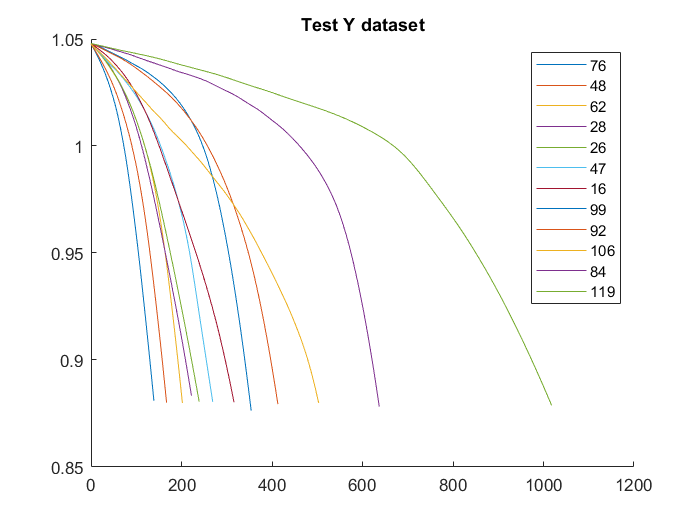

a = ryan4_battery_dataset(idxTest(1)).QDischargeSmooth;
b = ryan4_battery_dataset(idxTest(end)).QDischargeSmooth;
a1 = ryan4_battery_dataset(idxTest(2)).QDischargeSmooth;
b1 = ryan4_battery_dataset(idxTest(end-1)).QDischargeSmooth;

%https://kr.mathworks.com/matlabcentral/answers/146685-find-index-where-value-exceeds-threshold
[idxFirst] = find(a >= 1,1,'last')
[idxLast] = find(b >= 1,1,'last' )
idxLast = idxLast + 1
a(idxFirst-1)
a(idxFirst)
a(idxFirst+1)

b(idxLast-1)

b(idxLast)

cycle_life_list =      1    76   140
     2    48   168
     3    62   203
     4    28   222
     5    26   239
     6    47   270
     7    16   316
     8    99   355
     9    92   414
    10   106   504


b(idxLast+1)
[idxFirst] = find(a1 >= 1,1,'last')
[idxLast] = find(b1 >= 1,1,'last' )
idxLast = idxLast + 1

idxTestCount = 12

a1(idxFirst-1)

idxTestStopCount = 6

a1(idxFirst)

idxTestReverse = 12

a1(idxFirst+1)

b1(idxLast-1)
b1(idxLast)
b1(idxLast+1)




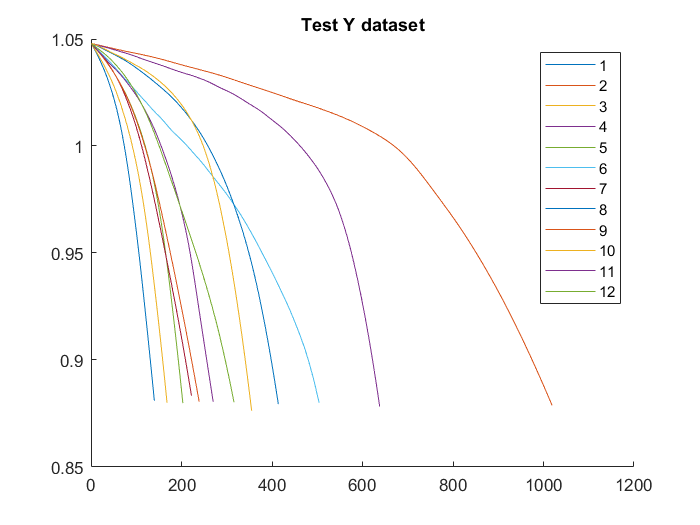

idxTestCount = length(idxTest)

nLines = length(idxTest);
legend_str = cell(nLines,1);

figure
hold on 
for j = 1 : idxTestCount
    i = idxTest(j);
    plot(ryan4_battery_dataset(i).cycle,ryan4_battery_dataset(i).QDischargeSmooth)
    cycle_life_list(j,:) = [j i ryan4_battery_dataset(i).cycle_life];
    legend_str{j} = num2str(i);
end
hold off
title 'Test Y dataset'
legend(legend_str)
cycle_life_list

battery_testset_org = zeros();

cycle_life_list_org =            1           1         140
           2           2        1019
           3           3         168
           4           4         638
           5           5         203
           6           6         504
           7           7         222
           8           8         414
           9           9         239
          10          10         355


battery_testset_org = ryan4_battery_dataset(idxTest(1));
idxTestCount = length(idxTest)
idxTestStopCount = idxTestCount / 2 
idxTestReverse = idxTestCount
k = 1;
kk = idxTestCount;
for j = 1 : idxTestStopCount
    pre = idxTest(j);

idxTestCount = 12

    post = idxTest(idxTestReverse);

idxTestStopCount = 6

    idxTestReverse = idxTestReverse - 1;

idxTestReverse = 12

    battery_testset_org(k,:) = ryan4_battery_dataset(pre);
    k=k+1;
    battery_testset_org(k,:) = ryan4_battery_dataset(post);
    k=k+1;
end

cycle_life_list = zeros();
cycle_life_list =  [ 1 1 1 ] ;

nLines = size(battery_testset_org,1);
legend_str = cell(nLines,1);
figure
hold on 
for i = 1 : nLines
    %plot(battery_testset(i).cycle,battery_testset(i).QDischargeSmooth)
    plot(battery_testset_org(i).QDischargeSmooth)
    cycle_life_list(i,:) = [i i battery_testset_org(i).cycle_life];
    legend_str{i} = num2str(i);
end

hold off
title 'Test Y dataset'
legend(legend_str)
cycle_life_list_org = cycle_life_list

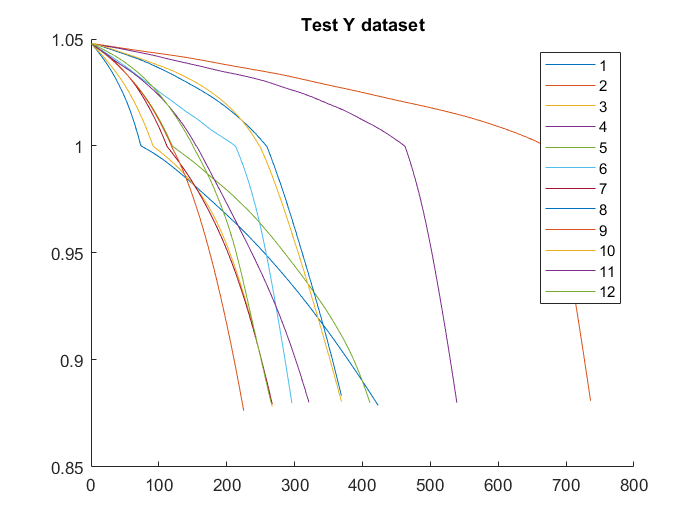

battery_testset = zeros();
battery_testset = ryan4_battery_dataset(idxTest(1));
%bat_pre = ryan4_battery_dataset(idxTest(1))
%bat_post = ryan4_battery_dataset(idxTest(12))
%battery_testset = bat_pre

idxTestCount = length(idxTest)
idxTestStopCount = idxTestCount / 2 
idxTestReverse = idxTestCount
k = 1;
kk = idxTestCount;
for j = 1 : idxTestStopCount
    pre = idxTest(j);
    post = idxTest(idxTestReverse);
    idxTestReverse = idxTestReverse - 1;
    
    %ryan4_battery_dataset(pre).QDischargeSmooth

    %cycle_life_list(j,:) = [j pre ryan4_battery_dataset(pre).cycle_life];

cycle_life_list_change =      1     1   423
     2     2   738
     3     3   267
     4     4   541
     5     5   411
     6     6   298
     7     7   267
     8     8   371
     9     9   225
    10    10   371


    %legend_str{j} = num2str(pre);
    
    [idxPre] = find(ryan4_battery_dataset(pre).QDischargeSmooth >= 1,1,'last');
    [idxPost] = find(ryan4_battery_dataset(post).QDischargeSmooth >= 1,1,'last' );
    idxPost = idxPost + 1;
    idxPreAfter = idxPre + 1;
    idxPreBefore = idxPre ;
    idxPostBefore = idxPost -1;
    idxPostAfter = idxPost ;
    
    battery_testset(k,:) = ryan4_battery_dataset(pre);
    
    battery_testset(k).IR([idxPreAfter:end],:) = [] ;
    battery_testset(k).QCharge([idxPreAfter:end],:) = [] ;
    battery_testset(k).QDischarge([idxPreAfter:end],:) = [] ;
    battery_testset(k).SOH_c([idxPreAfter:end],:) = [] ;
    battery_testset(k).SOH_d([idxPreAfter:end],:) = [] ;
    battery_testset(k).Time_c([idxPreAfter:end],:) = [] ;
    battery_testset(k).Time_d([idxPreAfter:end],:) = [] ;
    battery_testset(k).Time_d1([idxPreAfter:end],:) = [] ;    
    battery_testset(k).Tavg([idxPreAfter:end],:) = [] ;
    battery_testset(k).Tmin([idxPreAfter:end],:) = [] ;
    battery_testset(k).Tmax([idxPreAfter:end],:) = [] ;

    battery_testset(k).Vc([idxPreAfter:end],:) = [] ;
    battery_testset(k).Vd([idxPreAfter:end],:) = [] ;
    battery_testset(k).Tc([idxPreAfter:end],:) = [] ;
    battery_testset(k).Td([idxPreAfter:end],:) = [] ;
    battery_testset(k).Ic([idxPreAfter:end],:) = [] ;
    battery_testset(k).Id([idxPreAfter:end],:) = [] ;
    
    battery_testset(k).discharge_dQdV([idxPreAfter:end],:) = [] ;
    battery_testset(k).Qdlin([idxPreAfter:end],:) = [] ;
    battery_testset(k).Tdlin([idxPreAfter:end],:) = [] ;
    
    battery_testset(k).chargetime([idxPreAfter:end],:) = [] ;
    battery_testset(k).QDischargeSmooth([idxPreAfter:end],:) = [] ;
    
    battery_testset(k).IR = vertcat(battery_testset(k).IR,ryan4_battery_dataset(post).IR([idxPost:end],:)) ;

ans =     4.4001    4.3999    4.4005    4.4008    4.3997    4.3999    4.4003    4.4000    4.3999    4.4007    4.4002    4.4000    4.4000    4.3996    4.4000    4.3999    4.4006    4.4004    4.4001    4.3999    4.4001    4.4001    4.3996    4.3999    4.4000    4.3997    4.4000    4.3999    4.3999    4.4000    4.4000    4.4000    4.3999    4.3997    4.3999    4.4001    4.3998    4.3994    4.4008    4.3999    4.3997    4.4001    4.4003    4.3996    4.4001    4.4000    4.4000    4.3999    4.4008    4.3999
    4.4001    4.3999    4.4002    4.3998    4.4002    4.3995    4.4002    4.4000    4.4004    4.4002    4.3999    4.3991    4.3999    4.4001    4.4000    4.4001    4.4000    4.3999    4.4002    4.4003    4.4003    4.3999    4.4002    4.3999    4.4000    4.4001    4.4000    4.4000    4.4000    4.3999    4.4000    4.4000    4.4000    4.4001    4.4002    4.3998    4.3999    4.3997    4.4005    4.3995    4.4000    4.4001    4.4000    4.3998    4.4000    4.3999    4.4000    4.4001    4.4002   

    battery_testset(k).QCharge = vertcat(battery_testset(k).QCharge,ryan4_battery_dataset(post).QCharge([idxPost:end],:)) ;

ans =     4.4001    4.3999    4.4005    4.4008    4.3997    4.3999    4.4003    4.4000    4.3999    4.4007    4.4002    4.4000    4.4000    4.3996    4.4000    4.3999    4.4006    4.4004    4.4001    4.3999    4.4001    4.4001    4.3996    4.3999    4.4000    4.3997    4.4000    4.3999    4.3999    4.4000    4.4000    4.4000    4.3999    4.3997    4.3999    4.4001    4.3998    4.3994    4.4008    4.3999    4.3997    4.4001    4.4003    4.3996    4.4001    4.4000    4.4000    4.3999    4.4008    4.3999


    battery_testset(k).QDischarge = vertcat(battery_testset(k).QDischarge,ryan4_battery_dataset(post).QDischarge([idxPost:end],:)) ;
    battery_testset(k).SOH_c = vertcat(battery_testset(k).SOH_c,ryan4_battery_dataset(post).SOH_c([idxPost:end],:)) ;

Ic1 =     4.4001
    4.3999
    4.4005
    4.4008
    4.3997
    4.3999
    4.4003
    4.4000
    4.3999
    4.4007


    battery_testset(k).SOH_d = vertcat(battery_testset(k).SOH_d,ryan4_battery_dataset(post).SOH_d([idxPost:end],:)) ;
    battery_testset(k).Time_c = vertcat(battery_testset(k).Time_c,ryan4_battery_dataset(post).Time_c([idxPost:end],:)) ;
    battery_testset(k).Time_d = vertcat(battery_testset(k).Time_d,ryan4_battery_dataset(post).Time_d([idxPost:end],:)) ;

IcFirstFull = 0

    battery_testset(k).Time_d1 = vertcat(battery_testset(k).Time_d1,ryan4_battery_dataset(post).Time_d1([idxPost:end],:)) ;

IcFirstFull =     4.4001    4.3999    4.4005    4.4008    4.3997    4.3999    4.4003    4.4000    4.3999    4.4007    4.4002    4.4000    4.4000    4.3996    4.4000    4.3999    4.4006    4.4004    4.4001    4.3999    4.4001    4.4001    4.3996    4.3999    4.4000    4.3997    4.4000    4.3999    4.3999    4.4000    4.4000    4.4000    4.3999    4.3997    4.3999    4.4001    4.3998    4.3994    4.4008    4.3999    4.3997    4.4001    4.4003    4.3996    4.4001    4.4000    4.4000    4.3999    4.4008    4.3999


    battery_testset(k).Tavg = vertcat(battery_testset(k).Tavg,ryan4_battery_dataset(post).Tavg([idxPost:end],:)) ;
    battery_testset(k).Tmin = vertcat(battery_testset(k).Tmin,ryan4_battery_dataset(post).Tmin([idxPost:end],:)) ;

VdFirstFull = 0

    battery_testset(k).Tmax = vertcat(battery_testset(k).Tmax,ryan4_battery_dataset(post).Tmax([idxPost:end],:)) ;

VdFirstFull =     3.2974    3.2346    3.2033    3.1864    3.1762    3.1695    3.1647    3.1611    3.1577    3.1550    3.1523    3.1500    3.1480    3.1458    3.1436    3.1417    3.1397    3.1376    3.1356    3.1336    3.1315    3.1295    3.1275    3.1253    3.1232    3.1209    3.1188    3.1165    3.1142    3.1117    3.1093    3.1069    3.1044    3.1020    3.0993    3.0968    3.0942    3.0915    3.0888    3.0860    3.0832    3.0804    3.0775    3.0746    3.0716    3.0684    3.0652    3.0619    3.0584    3.0549


    battery_testset(k).Vc = vertcat(battery_testset(k).Vc,ryan4_battery_dataset(post).Vc([idxPost:end],:)) ;
    battery_testset(k).Vd = vertcat(battery_testset(k).Vd,ryan4_battery_dataset(post).Vd([idxPost:end],:)) ;
    battery_testset(k).Tc = vertcat(battery_testset(k).Tc,ryan4_battery_dataset(post).Tc([idxPost:end],:)) ;
    battery_testset(k).Td = vertcat(battery_testset(k).Td,ryan4_battery_dataset(post).Td([idxPost:end],:)) ;
    battery_testset(k).Ic = vertcat(battery_testset(k).Ic,ryan4_battery_dataset(post).Ic([idxPost:end],:)) ;
    battery_testset(k).Id = vertcat(battery_testset(k).Id,ryan4_battery_dataset(post).Id([idxPost:end],:)) ;
    

IcFirstFull =     4.4001    4.3999    4.4005    4.4008    4.3997    4.3999    4.4003    4.4000    4.3999    4.4007    4.4002    4.4000    4.4000    4.3996    4.4000    4.3999    4.4006    4.4004    4.4001    4.3999    4.4001    4.4001    4.3996    4.3999    4.4000    4.3997    4.4000    4.3999    4.3999    4.4000    4.4000    4.4000    4.3999    4.3997    4.3999    4.4001    4.3998    4.3994    4.4008    4.3999    4.3997    4.4001    4.4003    4.3996    4.4001    4.4000    4.4000    4.3999    4.4008    4.3999
    4.8000    4.8000    4.8000    4.7999    4.8001    4.8000    4.8001    4.8001    4.8001    4.8001    4.7998    4.8003    4.8000    4.8000    4.8001    4.8000    4.7998    4.8000    4.7999    4.7998    4.8000    4.7998    4.8001    4.8001    4.8000    4.7998    4.8000    4.8003    4.8001    4.8000    4.8001    4.8001    4.7999    4.8001    4.8000    4.8000    4.8003    4.8001    4.8000    4.8000    4.7999    4.7998    4.8001    4.8000    4.8003    4.8001    4.8001    4.8002    4

    battery_testset(k).discharge_dQdV = vertcat(battery_testset(k).discharge_dQdV,ryan4_battery_dataset(post).discharge_dQdV([idxPost:end],:)) ;

VdFirstFull =     3.2974    3.2346    3.2033    3.1864    3.1762    3.1695    3.1647    3.1611    3.1577    3.1550    3.1523    3.1500    3.1480    3.1458    3.1436    3.1417    3.1397    3.1376    3.1356    3.1336    3.1315    3.1295    3.1275    3.1253    3.1232    3.1209    3.1188    3.1165    3.1142    3.1117    3.1093    3.1069    3.1044    3.1020    3.0993    3.0968    3.0942    3.0915    3.0888    3.0860    3.0832    3.0804    3.0775    3.0746    3.0716    3.0684    3.0652    3.0619    3.0584    3.0549
    3.2991    3.2361    3.2046    3.1877    3.1774    3.1708    3.1659    3.1620    3.1587    3.1559    3.1532    3.1508    3.1485    3.1464    3.1442    3.1421    3.1399    3.1379    3.1358    3.1337    3.1316    3.1295    3.1272    3.1251    3.1227    3.1205    3.1182    3.1157    3.1133    3.1109    3.1085    3.1058    3.1033    3.1006    3.0980    3.0953    3.0925    3.0898    3.0870    3.0843    3.0812    3.0782    3.0753    3.0723    3.0690    3.0659    3.0626    3.0591    3

    battery_testset(k).Qdlin = vertcat(battery_testset(k).Qdlin,ryan4_battery_dataset(post).Qdlin([idxPost:end],:)) ;
    battery_testset(k).Tdlin = vertcat(battery_testset(k).Tdlin,ryan4_battery_dataset(post).Tdlin([idxPost:end],:)) ;

RulFirst =    428
   229
   253
   338
   416
   331
   278
   235
   284
   462


blockSize =      1     5


    battery_testset(k).chargetime = vertcat(battery_testset(k).chargetime,ryan4_battery_dataset(post).chargetime([idxPost:end],:)) ;

meanFilterFunction = function_handle with value:
    @(theBlockStructure)mean2(theBlockStructure.data(:))


    battery_testset(k).QDischargeSmooth = vertcat(battery_testset(k).QDischargeSmooth,ryan4_battery_dataset(post).QDischargeSmooth([idxPost:end],:)) ;

IcFirst =     4.4002    4.4002    4.4000    4.4002    4.4000    4.3999    4.3999    4.4000    4.3999    4.4001    4.4000    4.4000    4.3998    4.4001    2.8830    0.9999    1.0000    0.2486         0         0
    4.8000    4.8001    4.8000    4.7999    4.8000    4.8000    4.8000    4.8001    4.8000    4.8001    4.8000    4.8001    4.8001    4.4818    3.3432    1.0001    0.9999    0.1944         0         0
    4.8000    4.8000    4.7999    4.8000    4.8000    4.8000    4.8000    4.8000    4.8001    4.8000    4.7999    4.7999    4.7999    4.5428    3.2030    1.0000    1.0000    0.1975         0         0
    5.4000    5.3999    5.3998    5.3999    5.4002    5.4000    5.3997    4.3203    3.6000    3.6001    3.6000    3.6000    3.5999    3.6000    2.4843    1.0001    1.0000    0.2434         0         0
    5.3991    5.4004    5.3996    5.4003    5.3998    5.4004    5.4000    5.4001    5.4001    3.4802    2.9999    3.0000    3.0000    3.0000    2.1265    1.0001    1.0000    0.2224      

VdFirst =     3.2196    3.1616    3.1480    3.1376    3.1274    3.1164    3.1044    3.0915    3.0775    3.0618    3.0430    3.0193    2.9873    2.9403    2.8626    2.7141    2.3617    1.9999    1.9999    1.9999
    3.2210    3.1627    3.1486    3.1379    3.1272    3.1157    3.1032    3.0898    3.0752    3.0590    3.0393    3.0143    2.9807    2.9318    2.8535    2.7101    2.4012    1.9997    1.9997    1.9997
    3.2243    3.1647    3.1502    3.1395    3.1291    3.1180    3.1061    3.0930    3.0786    3.0623    3.0428    3.0180    2.9838    2.9316    2.8403    2.6536    2.2249    2.0000    2.0001    2.0001
    3.2252    3.1664    3.1529    3.1429    3.1330    3.1224    3.1109    3.0982    3.0845    3.0694    3.0516    3.0291    2.9986    2.9527    2.8755    2.7216    2.3358    1.9997    1.9997    1.9997
    3.2307    3.1771    3.1643    3.1540    3.1438    3.1328    3.1208    3.1078    3.0941    3.0795    3.0627    3.0419    3.0150    2.9765    2.9134    2.7898    2.4864    2.0033    2.

    battery_testset(k).cycle_life = idxPre +  (ryan4_battery_dataset(post).cycle_life - idxPost  ) + 1 ;
    battery_testset(k).cycle = [];
    battery_testset(k).cycle = linspace(1,battery_testset(k).cycle_life,battery_testset(k).cycle_life) ;

    battery_testset(k).QDischargePolyMdl = [];
%    battery_testset(k).QDischargePolyMdl = polyfit(battery_testset(k).cycle, battery_testset(k).QDischargeSmooth,4);
    battery_testset(k).QDischargePolyfit = [];
%    battery_testset(k).QDischargePolyfit = polyval(battery_testset.QDischargePolyMdl,battery_testset.cycle')';

%%%%%%%%%%%%%%%
    k = k+1;
    battery_testset(k,:) = ryan4_battery_dataset(post);
    
    battery_testset(k).IR([idxPostAfter:end],:) = [] ;
    battery_testset(k).QCharge([idxPostAfter:end],:) = [] ;
    battery_testset(k).QDischarge([idxPostAfter:end],:) = [] ;
    battery_testset(k).SOH_c([idxPostAfter:end],:) = [] ;
    battery_testset(k).SOH_d([idxPostAfter:end],:) = [] ;
    battery_testset(k).Time_c([idxPostAfter:end],:) = [] ;
    battery_testset(k).Time_d([idxPostAfter:end],:) = [] ;
    battery_testset(k).Time_d1([idxPostAfter:end],:) = [] ;
    battery_testset(k).Tavg([idxPostAfter:end],:) = [] ;

ans = logical
   1


    battery_testset(k).Tavg([idxPostAfter:end],:) = [] ;
    battery_testset(k).Tmin([idxPostAfter:end],:) = [] ;
    battery_testset(k).Tmax([idxPostAfter:end],:) = [] ;
    battery_testset(k).Vc([idxPostAfter:end],:) = [] ;
    battery_testset(k).Vd([idxPostAfter:end],:) = [] ;
    battery_testset(k).Tc([idxPostAfter:end],:) = [] ;

ans = logical
   1


    battery_testset(k).Td([idxPostAfter:end],:) = [] ;
    battery_testset(k).Ic([idxPostAfter:end],:) = [] ;
    battery_testset(k).Id([idxPostAfter:end],:) = [] ;

ans = logical
   1


ans = logical
   1


    battery_testset(k).discharge_dQdV([idxPostAfter:end],:) = [] ;

ans = logical
   1


    battery_testset(k).Qdlin([idxPostAfter:end],:) = [] ;

ans = logical
   1


    battery_testset(k).Tdlin([idxPostAfter:end],:) = [] ;
    

ynorm_First_RUL =     0.3004
    0.1130
    0.1356
    0.2156
    0.2891
    0.2090
    0.1591
    0.1186
    0.1648
    0.3324


    battery_testset(k).chargetime([idxPostAfter:end],:) = [] ;

ymax_First_RUL = 1171

    battery_testset(k).QDischargeSmooth([idxPostAfter:end],:) = [] ;

ymin_First_RUL = 109

yrate_First_RUL = 1062

    battery_testset(k).IR = vertcat(battery_testset(k).IR,ryan4_battery_dataset(pre).IR([idxPreAfter:end],:)) ;
    battery_testset(k).QCharge = vertcat(battery_testset(k).QCharge,ryan4_battery_dataset(pre).QCharge([idxPreAfter:end],:)) ;
    battery_testset(k).QDischarge = vertcat(battery_testset(k).QDischarge,ryan4_battery_dataset(pre).QDischarge([idxPreAfter:end],:)) ;
    battery_testset(k).SOH_c = vertcat(battery_testset(k).SOH_c,ryan4_battery_dataset(pre).SOH_c([idxPreAfter:end],:)) ;
    battery_testset(k).SOH_d = vertcat(battery_testset(k).SOH_d,ryan4_battery_dataset(pre).SOH_d([idxPreAfter:end],:)) ;
    battery_testset(k).Time_c = vertcat(battery_testset(k).Time_c,ryan4_battery_dataset(pre).Time_c([idxPreAfter:end],:)) ;
    battery_testset(k).Time_d = vertcat(battery_testset(k).Time_d,ryan4_battery_dataset(pre).Time_d([idxPreAfter:end],:)) ;
    battery_testset(k).Time_d1 = vertcat(battery_testset(k).Time_d1,ryan4_battery_dataset(pre).Time_d1([idxPreAfter:end],:)) ;
    battery_testset(k).Tavg = vertcat(battery_testset(k).Tavg,ryan4_battery_dataset(pre).Tavg([idxPreAfter:end],:)) ;
    battery_testset(k).Tmin = vertcat(battery_testset(k).Tmin,ryan4_battery_dataset(pre).Tmin([idxPreAfter:end],:)) ;
    battery_testset(k).Tmax = vertcat(battery_testset(k).Tmax,ryan4_battery_dataset(pre).Tmax([idxPreAfter:end],:)) ;
    battery_testset(k).Vc = vertcat(battery_testset(k).Vc,ryan4_battery_dataset(pre).Vc([idxPreAfter:end],:)) ;
    battery_testset(k).Vd = vertcat(battery_testset(k).Vd,ryan4_battery_dataset(pre).Vd([idxPreAfter:end],:)) ;
    battery_testset(k).Tc = vertcat(battery_testset(k).Tc,ryan4_battery_dataset(pre).Tc([idxPreAfter:end],:)) ;
    battery_testset(k).Td = vertcat(battery_testset(k).Td,ryan4_battery_dataset(pre).Td([idxPreAfter:end],:)) ;
    battery_testset(k).Ic = vertcat(battery_testset(k).Ic,ryan4_battery_dataset(pre).Ic([idxPreAfter:end],:)) ;
    battery_testset(k).Id = vertcat(battery_testset(k).Id,ryan4_battery_dataset(pre).Id([idxPreAfter:end],:)) ;
    
    battery_testset(k).discharge_dQdV = vertcat(battery_testset(k).discharge_dQdV,ryan4_battery_dataset(pre).discharge_dQdV([idxPreAfter:end],:)) ;
    battery_testset(k).Qdlin = vertcat(battery_testset(k).Qdlin,ryan4_battery_dataset(pre).Qdlin([idxPreAfter:end],:)) ;
    battery_testset(k).Tdlin = vertcat(battery_testset(k).Tdlin,ryan4_battery_dataset(pre).Tdlin([idxPreAfter:end],:)) ;   
     
    battery_testset(k).chargetime = vertcat(battery_testset(k).chargetime,ryan4_battery_dataset(pre).chargetime([idxPreAfter:end],:)) ;

ans = logical
   1


    battery_testset(k).QDischargeSmooth = vertcat(battery_testset(k).QDischargeSmooth,ryan4_battery_dataset(pre).QDischargeSmooth([idxPreAfter:end],:)) ;

ans = logical
   1


ans = logical
   1


    battery_testset(k).cycle_life = idxPost +  (ryan4_battery_dataset(pre).cycle_life - idxPre  ) + 1 ;

ans = logical
   1


    battery_testset(k).cycle = [];
    battery_testset(k).cycle = linspace(1,battery_testset(k).cycle_life,battery_testset(k).cycle_life) ;

    battery_testset(k).QDischargePolyMdl = [];
%    battery_testset(k).QDischargePolyMdl = polyfit(battery_testset(k).cycle, battery_testset(k).QDischargeSmooth,4);
    battery_testset(k).QDischargePolyfit = [];
%    battery_testset(k).QDischargePolyfit = polyval(battery_testset.QDischargePolyMdl,battery_testset.cycle')';
    k = k +1;
end
%battery_testset




cycle_life_list = zeros();
cycle_life_list =  [ 1 1 1 ] ;

nLines = size(battery_testset,1);
legend_str = cell(nLines,1);
figure
hold on 
for i = 1 : nLines

ans =     1.0479
    1.0478
    1.0477
    1.0476
    1.0475
    1.0474
    1.0473
    1.0472
    1.0471
    1.0470


    %plot(battery_testset(i).cycle,battery_testset(i).QDischargeSmooth)

ans =     3.2974    3.2346    3.2033    3.1864    3.1762    3.1695    3.1647    3.1611    3.1577    3.1550    3.1523    3.1500    3.1480    3.1458    3.1436    3.1417    3.1397    3.1376    3.1356    3.1336    3.1315    3.1295    3.1275    3.1253    3.1232    3.1209    3.1188    3.1165    3.1142    3.1117    3.1093    3.1069    3.1044    3.1020    3.0993    3.0968    3.0942    3.0915    3.0888    3.0860    3.0832    3.0804    3.0775    3.0746    3.0716    3.0684    3.0652    3.0619    3.0584    3.0549
    3.2967    3.2340    3.2026    3.1858    3.1756    3.1692    3.1643    3.1604    3.1574    3.1545    3.1520    3.1497    3.1475    3.1453    3.1433    3.1413    3.1392    3.1373    3.1353    3.1333    3.1313    3.1293    3.1272    3.1249    3.1229    3.1205    3.1184    3.1162    3.1137    3.1115    3.1091    3.1067    3.1042    3.1017    3.0990    3.0965    3.0939    3.0913    3.0885    3.0858    3.0831    3.0802    3.0772    3.0743    3.0712    3.0682    3.0649    3.0617    3.0581   

    plot(battery_testset(i).QDischargeSmooth)

ans =    428     1


    cycle_life_list(i,:) = [i i battery_testset(i).cycle_life];

ans = 428

    legend_str{i} = num2str(i);
end

hold off
title 'Test Y dataset'
legend(legend_str)
cycle_life_list_change = cycle_life_list


%{
cycle_life_list = zeros();
cycle_life_list =  [ 1 1 1 ] ;

nLines = length(idxTestSort);
legend_str = cell(nLines,1);
figure
hold on 
for j = 1 : length(idxTestSort)
    i = idxTestSort(j);
    plot(ryan4_battery_dataset(i).cycle,ryan4_battery_dataset(i).QDischargeSmooth)
    cycle_life_list(j,:) = [j i ryan4_battery_dataset(i).cycle_life];
    legend_str{j} = num2str(i);
end

hold off
title 'Test Y dataset'
legend(legend_str)
cycle_life_list
%}


save('ryan4_battery_dataset.mat','battery_testset' ,'-append')

idxTrainAll =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


save('ryan4_battery_dataset.mat','battery_testset_org' ,'-append')

idxTrainAll_batIndex =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1


%% load ryan4_gen_data.mat

idxValidAll =         2793        2794        2795        2796        2797        2798        2799        2800        2801        2802        2803        2804        2805        2806        2807        2808        2809        2810        2811        2812        2813        2814        2815        2816        2817        2818        2819        2820        2821        2822        2823        2824        2825        2826        2827        2828        2829        2830        2831        2832        2833        2834        2835        2836        2837        2838        2839        2840        2841        2842


idxValidAll_batIndex =     10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10


%{

idxTestAll =         4962        4963        4964        4965        4966        4967        4968        4969        4970        4971        4972        4973        4974        4975        4976        4977        4978        4979        4980        4981        4982        4983        4984        4985        4986        4987        4988        4989        4990        4991        4992        4993        4994        4995        4996        4997        4998        4999        5000        5001        5002        5003        5004        5005        5006        5007        5008        5009        5010        5011


load('ryan4_battery_dataset.mat','ryan4_battery_dataset' )

idxTestAll_batIndex =     16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16


load('ryan4_data.mat','idxAll' )


Cap =     1.0479
    1.0478
    1.0477
    1.0476
    1.0475
    1.0474
    1.0473
    1.0472
    1.0471
    1.0470


%}

VdFull =     3.2974    3.2346    3.2033    3.1864    3.1762    3.1695    3.1647    3.1611    3.1577    3.1550    3.1523    3.1500    3.1480    3.1458    3.1436    3.1417    3.1397    3.1376    3.1356    3.1336    3.1315    3.1295    3.1275    3.1253    3.1232    3.1209    3.1188    3.1165    3.1142    3.1117    3.1093    3.1069    3.1044    3.1020    3.0993    3.0968    3.0942    3.0915    3.0888    3.0860    3.0832    3.0804    3.0775    3.0746    3.0716    3.0684    3.0652    3.0619    3.0584    3.0549
    3.2967    3.2340    3.2026    3.1858    3.1756    3.1692    3.1643    3.1604    3.1574    3.1545    3.1520    3.1497    3.1475    3.1453    3.1433    3.1413    3.1392    3.1373    3.1353    3.1333    3.1313    3.1293    3.1272    3.1249    3.1229    3.1205    3.1184    3.1162    3.1137    3.1115    3.1091    3.1067    3.1042    3.1017    3.0990    3.0965    3.0939    3.0913    3.0885    3.0858    3.0831    3.0802    3.0772    3.0743    3.0712    3.0682    3.0649    3.0617    3.0581

첫번째 cycle의 충전전류를 얻는다.

idx = 1; % idxAll; 

IcFull =     4.4001    4.3999    4.4005    4.4008    4.3997    4.3999    4.4003    4.4000    4.3999    4.4007    4.4002    4.4000    4.4000    4.3996    4.4000    4.3999    4.4006    4.4004    4.4001    4.3999    4.4001    4.4001    4.3996    4.3999    4.4000    4.3997    4.4000    4.3999    4.3999    4.4000    4.4000    4.4000    4.3999    4.3997    4.3999    4.4001    4.3998    4.3994    4.4008    4.3999    4.3997    4.4001    4.4003    4.3996    4.4001    4.4000    4.4000    4.3999    4.4008    4.3999
    4.4001    4.3999    4.4002    4.3998    4.4002    4.3995    4.4002    4.4000    4.4004    4.4002    4.3999    4.3991    4.3999    4.4001    4.4000    4.4001    4.4000    4.3999    4.4002    4.4003    4.4003    4.3999    4.4002    4.3999    4.4000    4.4001    4.4000    4.4000    4.4000    4.3999    4.4000    4.4000    4.4000    4.4001    4.4002    4.3998    4.3999    4.3997    4.4005    4.3995    4.4000    4.4001    4.4000    4.3998    4.4000    4.3999    4.4000    4.4001    4.4002


ryan4_battery_dataset(idx).Ic

blockSize =      1     5


ryan4_battery_dataset(idx).Ic(1,:)

meanFilterFunction = function_handle with value:
    @(theBlockStructure)mean2(theBlockStructure.data(:))


% 열벡터로 바꾼다.
Ic1 = ryan4_battery_dataset(idx).Ic(1,:)'

Ic =     4.4002    4.4002    4.4000    4.4002    4.4000    4.3999    4.3999    4.4000    4.3999    4.4001    4.4000    4.4000    4.3998    4.4001    2.8830    0.9999    1.0000    0.2486         0         0
    4.4000    4.4001    4.3998    4.4001    4.4001    4.4000    4.4001    4.3999    4.4000    4.4001    4.3999    4.4002    4.4000    4.3999    3.5301    1.0000    1.0000    0.2441         0         0
    4.4002    4.3999    4.3997    4.3999    4.3999    4.3999    4.4001    4.3999    4.4000    4.4000    4.3999    4.3999    4.3999    4.4000    3.5213    1.0000    1.0001    0.2455         0         0
    4.3999    4.4001    4.3999    4.4000    4.4001    4.4000    4.4000    4.3999    4.4000    4.4001    4.4000    4.4002    4.4001    4.4000    3.2207    0.9999    1.0000    0.2351         0         0
    4.3998    4.4001    4.4001    4.4001    4.4003    4.4000    4.3999    4.4000    4.4000    4.4000    4.3996    4.4000    4.3997    4.4000    3.1733    1.0002    1.0000    0.2350         0 

% 전체 데이타에 대해서 
IcFirstFull = zeros()

Vd =     3.2196    3.1616    3.1480    3.1376    3.1274    3.1164    3.1044    3.0915    3.0775    3.0618    3.0430    3.0193    2.9873    2.9403    2.8626    2.7141    2.3617    1.9999    1.9999    1.9999
    3.2189    3.1612    3.1476    3.1373    3.1271    3.1161    3.1041    3.0912    3.0772    3.0615    3.0427    3.0190    2.9870    2.9400    2.8623    2.7139    2.3606    1.9998    1.9999    1.9999
    3.2198    3.1619    3.1482    3.1378    3.1275    3.1165    3.1045    3.0915    3.0775    3.0617    3.0430    3.0193    2.9872    2.9401    2.8621    2.7126    2.3576    1.9999    2.0000    2.0000
    3.2194    3.1614    3.1478    3.1375    3.1272    3.1162    3.1042    3.0912    3.0772    3.0615    3.0428    3.0190    2.9870    2.9398    2.8618    2.7126    2.3529    2.0001    2.0004    2.0004
    3.2192    3.1612    3.1477    3.1374    3.1272    3.1162    3.1042    3.0913    3.0773    3.0616    3.0429    3.0191    2.9871    2.9400    2.8620    2.7127    2.3598    1.9999    2.0000 

IcFirstFull = ryan4_battery_dataset(1).Ic(1,:)

VdFirstFull = zeros()
VdFirstFull = ryan4_battery_dataset(1).Vd(1,:)

%IcFirstFull = ryan4_battery_dataset(2).Ic(1,:)
for i=1:length(ryan4_battery_dataset)
    IcFirstFull(i,:) = ryan4_battery_dataset(i).Ic(1,:);
    VdFirstFull(i,:) = ryan4_battery_dataset(i).Vd(1,:);
end
IcFirstFull
VdFirstFull
%IcFirstFull = IcFirstFull'
RulFirst = [ryan4_battery_dataset(idxAll).cycle_life ]'
blockSize = [1, 5] % 다섯개를 묶어서.
meanFilterFunction = @(theBlockStructure) mean2(theBlockStructure.data(:))
IcFirst = blockproc(IcFirstFull, blockSize, meanFilterFunction)
VdFirst = blockproc(VdFirstFull, blockSize, meanFilterFunction)
%RulFirst = cycleLife;
%clear cycleLife

%{
load("ryan4_data.mat",'RulFirst')
load("ryan4_data.mat",'IcFirstFull')
load("ryan4_data.mat",'IcFirst')
load("ryan4_data.mat",'VdFirstFull')
load("ryan4_data.mat",'VdFirst')

load("ryan4_data.mat",'idxA;;')
load("ryan4_data.mat",'idxTrain')

x_trainValid_Ic_RUL =     0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.4132    0.1976    0.1976    0.1115    0.0830    0.0830
    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.4874    0.1976    0.1976    0.1110    0.0830    0.0830
    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.4864    0.1976    0.1976    0.1111    0.0830    0.0830
    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.4519    0.1976    0.1976    0.1100    0.0830    0.0830
    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5869    0.5870    0.5870    0.5870    0.4465    0.1976    0.1976    

load("ryan4_data.mat",'idxValid')

x_test_Ic_RUL =     0.7703    0.7703    0.7702    0.7703    0.7702    0.7703    0.7702    0.5641    0.4266    0.4266    0.4266    0.4266    0.4266    0.4267    0.3269    0.1976    0.1976    0.1103    0.0830    0.0830
    0.7703    0.7703    0.7702    0.7702    0.7702    0.7703    0.7702    0.5641    0.4266    0.4266    0.4266    0.4266    0.4266    0.4266    0.3266    0.1976    0.1976    0.1093    0.0830    0.0830
    0.7702    0.7702    0.7703    0.7703    0.7703    0.7702    0.7703    0.5641    0.4266    0.4266    0.4266    0.4266    0.4267    0.4266    0.3265    0.1976    0.1976    0.1093    0.0830    0.0830
    0.7703    0.7703    0.7702    0.7702    0.7703    0.7703    0.7703    0.5641    0.4267    0.4266    0.4266    0.4266    0.4266    0.4266    0.3267    0.1976    0.1976    0.1087    0.0830    0.0830
    0.7703    0.7703    0.7703    0.7703    0.7703    0.7702    0.7702    0.5641    0.4267    0.4266    0.4266    0.4266    0.4266    0.4266    0.3268    0.1976    0.1976    0.1084

load("ryan4_data.mat",'idxTest')

y_trainValid_Ic_RUL =     0.3650
    0.3641
    0.3632
    0.3624
    0.3615
    0.3607
    0.3598
    0.3590
    0.3581
    0.3573


y_test_Ic_RUL =     0.2692
    0.2684
    0.2675
    0.2667
    0.2658
    0.2650
    0.2641
    0.2632
    0.2624
    0.2615


%}

[ynorm_IcFirst_RUL,ymax_IcFirst_RUL,ymin_IcFirst_RUL,yrate_IcFirst_RUL,xnorm_IcFirstFull_RUL,xmax_IcFirst_RUL,xmin_IcFirst_RUL,xrate_IcFirst_RUL] = ...

x_trainValid_Vd_RUL =     0.9175    0.8739    0.8637    0.8559    0.8482    0.8400    0.8309    0.8212    0.8107    0.7989    0.7848    0.7670    0.7429    0.7076    0.6493    0.5376    0.2728    0.0009    0.0009    0.0009
    0.9170    0.8736    0.8634    0.8556    0.8480    0.8397    0.8307    0.8210    0.8105    0.7987    0.7846    0.7668    0.7427    0.7074    0.6490    0.5375    0.2720    0.0009    0.0009    0.0009
    0.9177    0.8742    0.8638    0.8560    0.8483    0.8400    0.8310    0.8212    0.8107    0.7989    0.7848    0.7670    0.7429    0.7075    0.6489    0.5365    0.2698    0.0009    0.0010    0.0010
    0.9173    0.8737    0.8635    0.8558    0.8481    0.8398    0.8308    0.8210    0.8105    0.7987    0.7846    0.7668    0.7427    0.7072    0.6486    0.5365    0.2662    0.0011    0.0013    0.0013
    0.9172    0.8736    0.8635    0.8557    0.8480    0.8398    0.8308    0.8211    0.8106    0.7988    0.7847    0.7669    0.7428    0.7074    0.6488    0.5366    0.2714    

minmax_norm_new(RulFirst,IcFirstFull);

x_test_Vd_RUL =     0.9222    0.8786    0.8682    0.8605    0.8527    0.8443    0.8352    0.8253    0.8147    0.8028    0.7886    0.7704    0.7458    0.7088    0.6464    0.5239    0.2329    0.0010    0.0011    0.0011
    0.9218    0.8783    0.8680    0.8601    0.8523    0.8440    0.8348    0.8250    0.8143    0.8024    0.7881    0.7699    0.7451    0.7080    0.6451    0.5216    0.2288    0.0009    0.0008    0.0008
    0.9217    0.8781    0.8678    0.8599    0.8521    0.8438    0.8346    0.8247    0.8141    0.8022    0.7878    0.7697    0.7448    0.7076    0.6446    0.5207    0.2269    0.0011    0.0011    0.0011
    0.9221    0.8784    0.8680    0.8602    0.8524    0.8440    0.8349    0.8249    0.8142    0.8023    0.7880    0.7698    0.7449    0.7077    0.6444    0.5201    0.2233    0.0009    0.0009    0.0009
    0.9222    0.8786    0.8682    0.8603    0.8525    0.8441    0.8349    0.8250    0.8143    0.8025    0.7881    0.7699    0.7450    0.7076    0.6442    0.5194    0.2209    0.0010

[ynorm_IcFirst_RUL1,xnorm_IcFirst_RUL] = minmax_norm_new_with_param(RulFirst,IcFirst,ymin_IcFirst_RUL,yrate_IcFirst_RUL,xmin_IcFirst_RUL,xrate_IcFirst_RUL);

y_trainValid_Vd_RUL =     0.3650
    0.3641
    0.3632
    0.3624
    0.3615
    0.3607
    0.3598
    0.3590
    0.3581
    0.3573


% https://stackoverflow.com/questions/40053450/compare-if-two-vectors-are-the-same

y_test_Vd_RUL =     0.2692
    0.2684
    0.2675
    0.2667
    0.2658
    0.2650
    0.2641
    0.2632
    0.2624
    0.2615


all(ynorm_IcFirst_RUL == ynorm_IcFirst_RUL1)

[ynorm_VdFirst_RUL,ymax_VdFirst_RUL,ymin_VdFirst_RUL,yrate_VdFirst_RUL,xnorm_VdFirstFull_RUL,xmax_VdFirst_RUL,xmin_VdFirst_RUL,xrate_VdFirst_RUL] = ...

ans = logical
   1


minmax_norm_new(RulFirst,VdFirstFull);

ans = logical
   1


[ynorm_VdFirst_RUL1,xnorm_VdFirst_RUL] = minmax_norm_new_with_param(RulFirst,VdFirst,ymin_VdFirst_RUL,yrate_VdFirst_RUL,xmin_VdFirst_RUL,xrate_VdFirst_RUL);

ans = logical
   1


% https://stackoverflow.com/questions/40053450/compare-if-two-vectors-are-the-same

ans = logical
   1


all(ynorm_VdFirst_RUL == ynorm_VdFirst_RUL1)

ans = logical
   1


all(ynorm_IcFirst_RUL == ynorm_VdFirst_RUL)
all(ymax_IcFirst_RUL == ymax_VdFirst_RUL)
all(ymin_IcFirst_RUL == ymin_VdFirst_RUL)
all(yrate_IcFirst_RUL == yrate_VdFirst_RUL)

ynorm_First_RUL = ynorm_IcFirst_RUL
ymax_First_RUL = ymax_IcFirst_RUL
ymin_First_RUL = ymin_IcFirst_RUL
yrate_First_RUL = yrate_IcFirst_RUL

x_trainValid_IcFirstFull_RUL = xnorm_IcFirstFull_RUL([idxTrain idxValid],:);
x_test_IcFirstFull_RUL = xnorm_IcFirstFull_RUL([idxTest],:);
x_trainValid_IcFirst_RUL = xnorm_IcFirst_RUL([idxTrain idxValid],:);
x_test_IcFirst_RUL = xnorm_IcFirst_RUL([idxTest],:);

y_trainValid_IcFirst_RUL = ynorm_IcFirst_RUL([idxTrain idxValid]);
y_test_IcFirst_RUL = ynorm_IcFirst_RUL([idxTest]);
Y_trainValid_IcFirst_RUL = RulFirst([idxTrain idxValid]);
Y_test_IcFirst_RUL = RulFirst([idxTest]);


x_trainValid_VdFirstFull_RUL = xnorm_VdFirstFull_RUL([idxTrain idxValid],:);
x_test_VdFirstFull_RUL = xnorm_VdFirstFull_RUL([idxTest],:);
x_trainValid_VdFirst_RUL = xnorm_VdFirst_RUL([idxTrain idxValid],:);
x_test_VdFirst_RUL = xnorm_VdFirst_RUL([idxTest],:);

y_trainValid_VdFirst_RUL = ynorm_VdFirst_RUL([idxTrain idxValid]);
y_test_VdFirst_RUL = ynorm_VdFirst_RUL([idxTest]);
Y_trainValid_VdFirst_RUL = RulFirst([idxTrain idxValid]);
Y_test_VdFirst_RUL = RulFirst([idxTest]);

all(y_trainValid_IcFirst_RUL == y_trainValid_VdFirst_RUL)
all(y_test_IcFirst_RUL == y_test_VdFirst_RUL)
all(Y_trainValid_IcFirst_RUL == Y_trainValid_VdFirst_RUL)
all(Y_test_IcFirst_RUL == Y_test_VdFirst_RUL)

y_trainValid_First_RUL = y_trainValid_IcFirst_RUL ;
y_test_First_RUL = y_test_IcFirst_RUL ;
Y_trainValid_First_RUL = Y_trainValid_IcFirst_RUL ;
Y_test_First_RUL = Y_test_IcFirst_RUL ;


# 변수 추출

Cap = zeros();
Cap_c = zeros();
%SOH = zeros();
% = zeeros();
IcFull = zeros();
IdFull = zeros();
VcFull = zeros();
VdFull = zeros();
TcFull = zeros();
TdFull = zeros();

%VdFull = [1:100];
ryan4_battery_dataset(1).QDischargeSmooth
ryan4_battery_dataset(1).Vd
size(ryan4_battery_dataset(1).QDischargeSmooth)

cap_min =     0.8797    0.8776    0.8811    0.8808    0.8807    0.8799    0.8829    0.8812    0.8832    0.8813    0.8809    0.8814    0.8831    0.8804    0.8800    0.8802    0.8807    0.8814    0.8806    0.8805    0.8805    0.8813    0.8809    0.8795    0.8829    0.8805    0.8825    0.8834    0.8810    0.8799    0.8809    0.8819    0.8803    0.8805    0.8805    0.8813    0.8809    0.8804    0.8814    0.8812    0.8802    0.8805    0.8806    0.8808    0.8805    0.8806    0.8805    0.8801    0.8798    0.8800


length(ryan4_battery_dataset(1).QDischargeSmooth)

ans = 0.8763

ans = 0.8851

idxAll = (1:length(ryan4_battery_dataset));

Cap_EOL = 0.8804

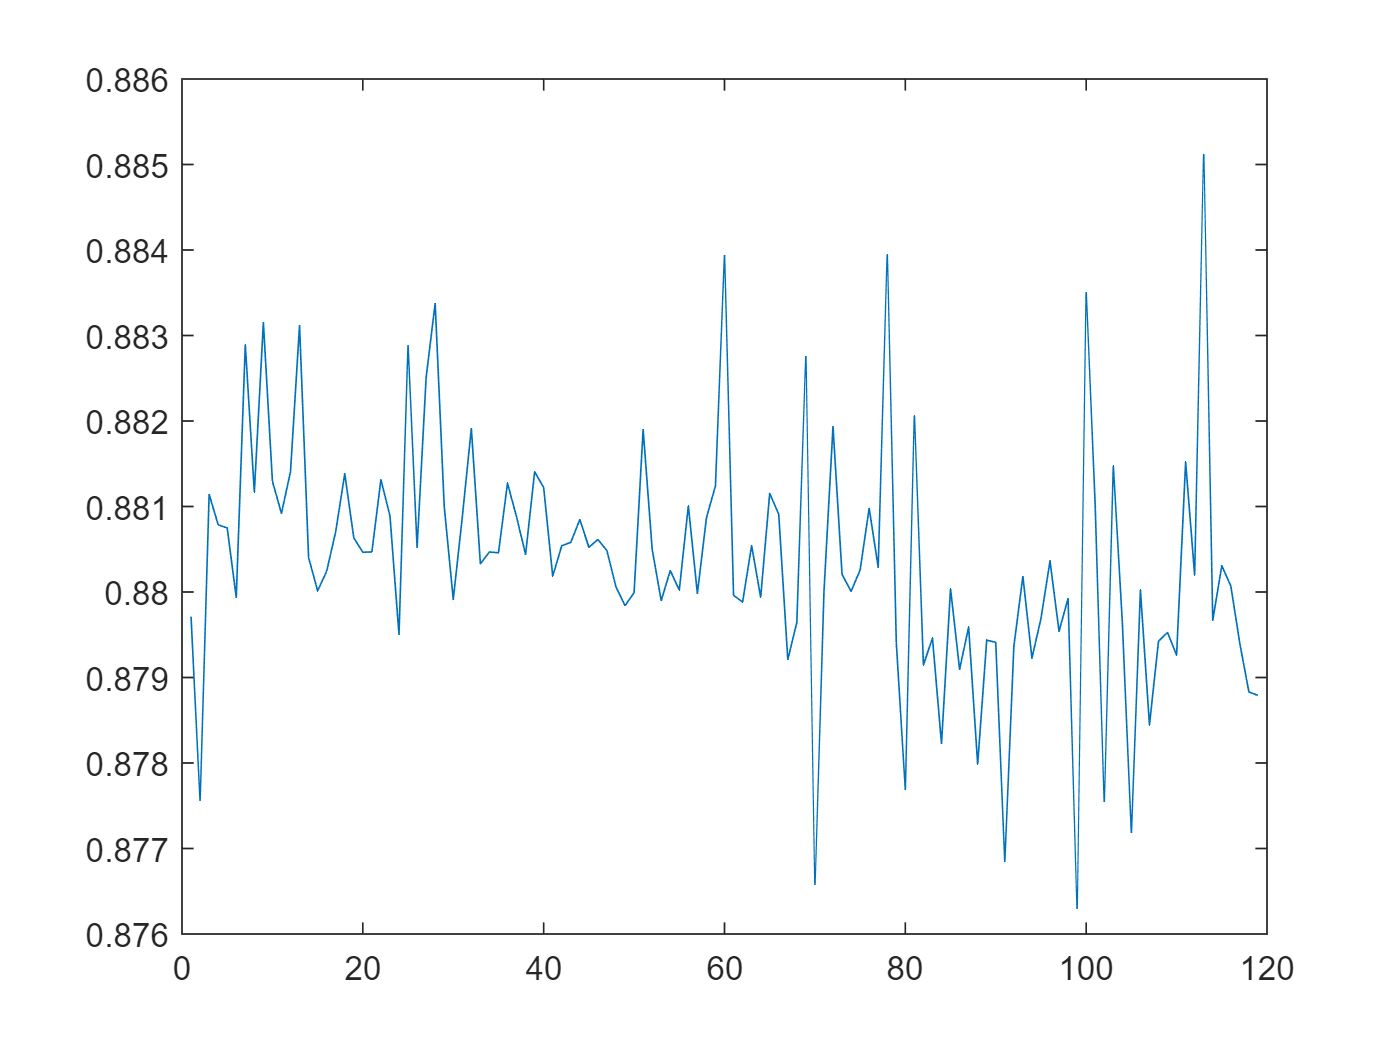

idxTrainValid = [ idxTrain idxValid ];

idxTrainAll = []; %zeros();
idxValidAll = []; %zeros();
idxTestAll = []; %zeros();
idxAllAll = []; %zeros();
idxTrainAll_batIndex = []; %zeros();

cap_max =     1.0479    1.0477    1.0476    1.0478    1.0479    1.0478    1.0478    1.0478    1.0477    1.0479    1.0476    1.0477    1.0477    1.0478    1.0479    1.0477    1.0477    1.0477    1.0478    1.0478    1.0476    1.0477    1.0478    1.0474    1.0476    1.0477    1.0477    1.0476    1.0476    1.0474    1.0477    1.0478    1.0475    1.0479    1.0475    1.0476    1.0473    1.0463    1.0476    1.0474    1.0477    1.0476    1.0476    1.0477    1.0477    1.0476    1.0477    1.0475    1.0478    1.0478


idxValidAll_batIndex = []; %zeros();

ans = 1.0463

idxTestAll_batIndex = []; %zeros();

ans = 1.0500

idxAllAll_batIndex = []; %zeros();

Cap_Rated = 1.0477

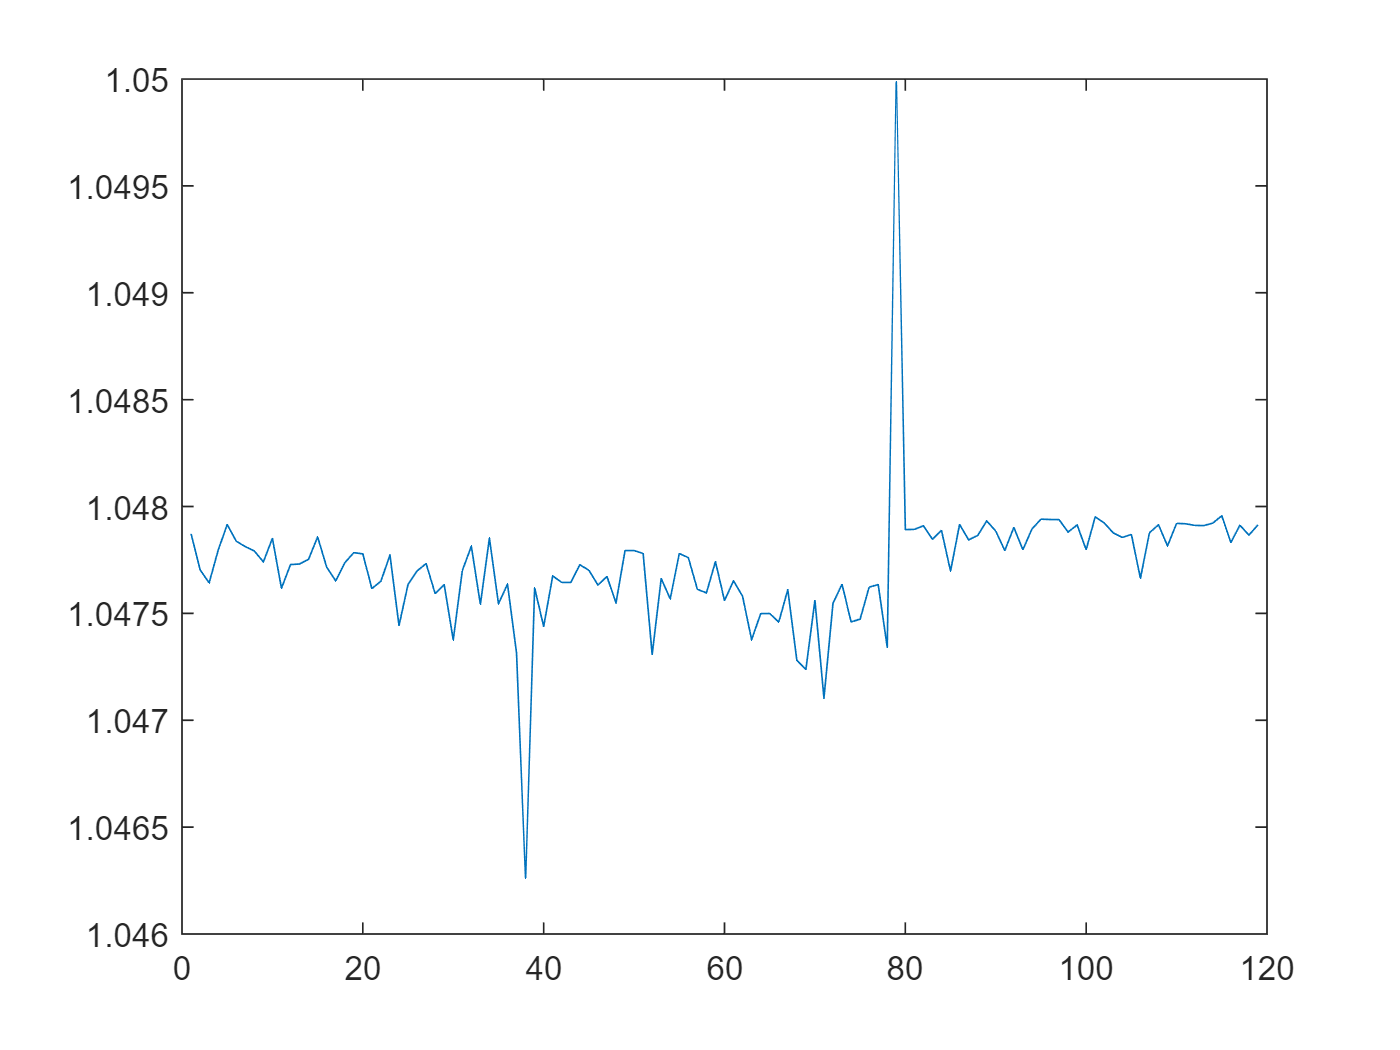

%batIndex_temp = [];

j =1;
startIndx = j ;
GenerateFrameList = @(A,S,N) A+S*(0:N-1);

for i = 1: length(idxAll)
        
    cap_temp = ryan4_battery_dataset(i).QDischargeSmooth;
    cap_c_temp = ryan4_battery_dataset(i).QDischargeSmooth;

    %SOH_temp = max(cap_temp);
    RUL_temp = linspace(ryan4_battery_dataset(i).cycle_life,1,ryan4_battery_dataset(i).cycle_life)';
    leng = length(cap_temp);

RulDiff =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1


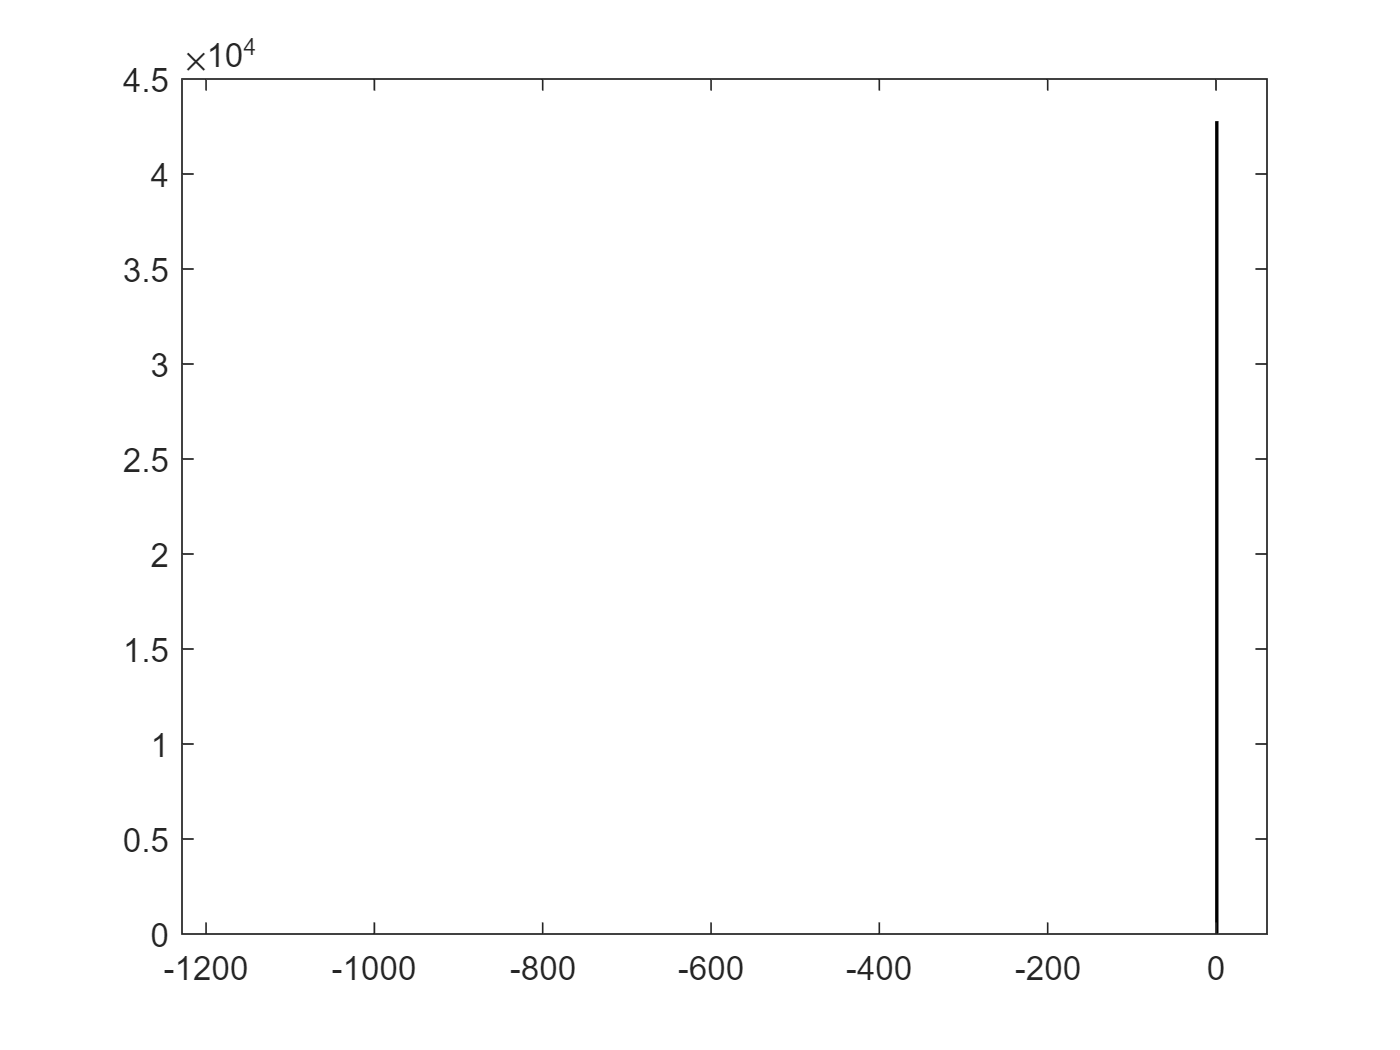

    
    %startIndx = j ;

    % https://kr.mathworks.com/matlabcentral/answers/478553-how-can-i-have-a-starting-number-a-step-size-then-the-number-of-numbers-i-need-in-a-1d-array
    append_index = GenerateFrameList(startIndx,1,leng);
    
    Vd_temp = ryan4_battery_dataset(i).Vd ;
    Vc_temp = ryan4_battery_dataset(i).Vc ;
    Td_temp = ryan4_battery_dataset(i).Td ;
    Tc_temp = ryan4_battery_dataset(i).Tc ;
    Id_temp = ryan4_battery_dataset(i).Id ;
    Ic_temp = ryan4_battery_dataset(i).Ic ;
    batIndex_temp = [];
    batIndex_temp(1:leng, 1) = i;
    %VdFull = [VdFull ; Vd_temp];
    if  i == 1

        Cap = cap_temp; 
        Cap_c = cap_c_temp;
        RUL = RUL_temp;

        VdFull = Vd_temp ;
        VcFull = Vc_temp ;
        TdFull = Td_temp ;
        TcFull = Tc_temp ;
        IdFull = Id_temp ;
        IcFull = Ic_temp ;


    else
        Cap = vertcat(Cap,cap_temp);
        Cap_c = vertcat(Cap_c,cap_c_temp);
        RUL = vertcat(RUL,RUL_temp);

        VdFull = vertcat(VdFull , Vd_temp );
        VcFull = vertcat(VcFull , Vc_temp );
        TdFull = vertcat(TdFull , Td_temp );
        TcFull = vertcat(TcFull , Tc_temp );
        IdFull = vertcat(IdFull , Id_temp );
        IcFull = vertcat(IcFull , Ic_temp );
    end
       
    idxAllAll =  [idxAllAll append_index ] ;
    idxAllAll_batIndex = [idxAllAll_batIndex batIndex_temp'];

    if any(idxTrain(:) == i) 
       % https://kr.mathworks.com/matlabcentral/answers/283821-add-single-element-to-array-or-vector
       idxTrainAll =  [idxTrainAll append_index ] ;
       idxTrainAll_batIndex = [idxTrainAll_batIndex batIndex_temp'];
    end
    if any(idxValid(:) == i) 
       idxValidAll =  [idxValidAll append_index ] ;
       idxValidAll_batIndex = [idxValidAll_batIndex batIndex_temp'];
    end
    if any(idxTest(:) == i) 
       idxTestAll =  [idxTestAll append_index ] ;
       idxTestAll_batIndex = [idxTestAll_batIndex batIndex_temp'];
    end
    %VdFull(i) = Vd_temp;
    
    startIndx = startIndx + leng;
end


idxTrainAll
idxTrainAll_batIndex
idxValidAll
idxValidAll_batIndex
idxTestAll
idxTestAll_batIndex

Cap
VdFull
IcFull
% https://kr.mathworks.com/matlabcentral/answers/80480-how-do-i-take-the-average-of-every-n-values-in-a-vector
blockSize = [1, 5] % 다섯개를 묶어서.
meanFilterFunction = @(theBlockStructure) mean2(theBlockStructure.data(:))

Ic = blockproc(IcFull, blockSize, meanFilterFunction)
%clear IcFull  

Vd = blockproc(VdFull, blockSize, meanFilterFunction)
%clear VdFull  
Vc = blockproc(VcFull, blockSize, meanFilterFunction);
Td = blockproc(TdFull, blockSize, meanFilterFunction);
Tc = blockproc(TcFull, blockSize, meanFilterFunction);
Id = blockproc(IdFull, blockSize, meanFilterFunction);



%ryan4_gen_data_raw_desc = "ryan4_gen_data_raw_desc";
%save('ryan4_data_raw.mat','ryan4_gen_data_raw_desc');
%save('ryan4_data_raw.mat','ryan4_battery_dataset','-append');



% https://stackoverflow.com/questions/39149677/how-to-delete-a-variable-from-mat-file-in-matlab
%rmmatvar('ryan4_gen_data.mat', 'ryan4_battery_dataset');

%clear ryan4_battery_dataset


[ynorm_Ic_RUL,ymax_Ic_RUL,ymin_Ic_RUL,yrate_Ic_RUL,xnorm_Ic_RUL,xmax_Ic_RUL,xmin_Ic_RUL,xrate_Ic_RUL] = minmax_norm_new(RUL,Ic);
[ynorm_Vd_RUL,ymax_Vd_RUL,ymin_Vd_RUL,yrate_Vd_RUL,xnorm_Vd_RUL,xmax_Vd_RUL,xmin_Vd_RUL,xrate_Vd_RUL] = minmax_norm_new(RUL,Vd);

Y_trainValid_Ic_RUL = RUL([idxTrainAll idxValidAll],:);
Y_test_Ic_RUL = RUL([idxTestAll],:);
x_trainValid_Ic_RUL = xnorm_Ic_RUL([idxTrainAll idxValidAll],:)
x_test_Ic_RUL = xnorm_Ic_RUL([idxTestAll],:)
y_trainValid_Ic_RUL = ynorm_Ic_RUL([idxTrainAll idxValidAll])
y_test_Ic_RUL = ynorm_Ic_RUL([idxTestAll])
Y_trainValid_Vd_RUL = RUL([idxTrainAll idxValidAll],:);
Y_test_Vd_RUL = RUL([idxTestAll],:);
x_trainValid_Vd_RUL = xnorm_Vd_RUL([idxTrainAll idxValidAll],:)
x_test_Vd_RUL = xnorm_Vd_RUL([idxTestAll],:)
y_trainValid_Vd_RUL = ynorm_Vd_RUL([idxTrainAll idxValidAll])
y_test_Vd_RUL = ynorm_Vd_RUL([idxTestAll])


all(Y_trainValid_Ic_RUL == Y_trainValid_Vd_RUL)
all(Y_test_Ic_RUL == Y_test_Vd_RUL)
all(y_trainValid_Ic_RUL == y_trainValid_Vd_RUL)
all(y_test_Ic_RUL == y_test_Vd_RUL)

all(ynorm_Ic_RUL == ynorm_Vd_RUL)
ynorm_RUL = ynorm_Ic_RUL ;
ymax_RUL = ymax_Ic_RUL ;
ymin_RUL = ymin_Ic_RUL ;
yrate_RUL = yrate_Ic_RUL ;


Y_trainValid_RUL = Y_trainValid_Vd_RUL ;
Y_test_RUL = Y_test_Vd_RUL ;
y_trainValid_RUL = y_trainValid_Vd_RUL ;
y_test_RUL = y_test_Vd_RUL ;

[ynorm_SOH,ymax_SOH,ymin_SOH,yrate_SOH,xnorm_Ic_SOH,xmax_Ic_SOH,xmin_Ic_SOH,xrate_Ic_SOH] = minmax_norm_new(Cap,Ic);
[ynorm_SOH,ymax_SOH,ymin_SOH,yrate_SOH,xnorm_Vd_SOH,xmax_Vd_SOH,xmin_Vd_SOH,xrate_Vd_SOH] = minmax_norm_new(Cap,Vd);


Y_trainValid_SOH = Cap([idxTrainAll idxValidAll],:);
Y_test_SOH = Cap([idxTestAll],:);
y_trainValid_SOH = ynorm_SOH([idxTrainAll idxValidAll]);
y_test_SOH = ynorm_SOH([idxTestAll]);

x_trainValid_Ic_SOH = xnorm_Ic_SOH([idxTrainAll idxValidAll],:);
x_test_Ic_SOH = xnorm_Ic_SOH([idxTestAll],:);
x_trainValid_Vd_SOH = xnorm_Vd_SOH([idxTrainAll idxValidAll],:);
x_test_Vd_SOH = xnorm_Vd_SOH([idxTestAll],:);



[xnorm_Tc,xmax_Tc,xmin_Tc,xrate_Tc] = minmax_norm_x(Tc);
x_trainValid_Tc = xnorm_Tc([idxTrainAll idxValidAll],:);
x_test_Tc = xnorm_Tc([idxTestAll],:);

[xnorm_Td,xmax_Td,xmin_Td,xrate_Td] = minmax_norm_x(Td);
x_trainValid_Td = xnorm_Td([idxTrainAll idxValidAll],:);
x_test_Td = xnorm_Td([idxTestAll],:);

[xnorm_Vc,xmax_Vc,xmin_Vc,xrate_Vc] = minmax_norm_x(Vc);
x_trainValid_Vc = xnorm_Vc([idxTrainAll idxValidAll],:);
x_test_Vc = xnorm_Vc([idxTestAll],:);

[xnorm_Id,xmax_Id,xmin_Id,xrate_Id] = minmax_norm_x(Id);
x_trainValid_Id = xnorm_Id([idxTrainAll idxValidAll],:);
x_test_Id = xnorm_Id([idxTestAll],:);

[ynorm_SOHc,ymax_SOHc,ymin_SOHc,yrate_SOHc] = minmax_norm_x(Cap_c);

Y_trainValid_SOHc = Cap_c([idxTrainAll idxValidAll],:);
Y_test_SOHc = Cap_c([idxTestAll],:);
y_trainValid_SOHc = ynorm_SOHc([idxTrainAll idxValidAll]);
y_test_SOHc = ynorm_SOHc([idxTestAll]);

cap_min = zeros();
for i = 1: length(idxAll)
    cap_min = [cap_min min(ryan4_battery_dataset(i).QDischargeSmooth)];
end
cap_min = cap_min(2:end)
min(cap_min)
max(cap_min)
Cap_EOL = mean(cap_min)
plot(cap_min)
cap_max = zeros();
for i = 1: length(idxAll)
    cap_max = [cap_max max(ryan4_battery_dataset(i).QDischargeSmooth)];
end
cap_max = cap_max(2:end)
min(cap_max)
max(cap_max)
Cap_Rated = mean(cap_max)
plot(cap_max)

CapDiff = diff(Cap).*(-1);
% plot(CapDiff); % 다음 베티러 셋으로 갈때 Cap 이 값자기 증가하고 이전에 마이너스를 했기 때문에 마이너스 값을 갖는다.
% histogram(CapDiff)
newBatIndex = find(CapDiff < -0.02);
newBatIndex_next = newBatIndex + 1;
CapDiff(newBatIndex) = CapDiff(newBatIndex_next);
CapDiff = [ CapDiff(1) ; CapDiff];
% plot(CapDiff)
% A =  [ 1 2 3 ]
% A([1 2]) = A([ 2 3])
RulDiff = diff(RUL).*(-1)
% plot(RulDiff); % 다음 베티러 셋으로 갈때 RUL 이 값자기 증가하고 이전에 마이너스를 했기 때문에 마이너스 값을 갖는다.
histogram(RulDiff);
newBatIndex = find(RulDiff < -10);
newBatIndex_next = newBatIndex + 1;
RulDiff(newBatIndex) = RulDiff(newBatIndex_next);
RulDiff = [ RulDiff(1) ; RulDiff];
% plot(RulDiff);

[ynorm_DeltaSOH,ymax_DeltaSOH,ymin_DeltaSOH,yrate_DeltaSOH] = minmax_norm_x(CapDiff);

Y_trainValid_DeltaSOH = CapDiff([idxTrainAll idxValidAll],:);
Y_test_DeltaSOH = CapDiff([idxTestAll],:);
y_trainValid_DeltaSOH = ynorm_DeltaSOH([idxTrainAll idxValidAll]);
y_test_DeltaSOH = ynorm_DeltaSOH([idxTestAll]);

[ynorm_DeltaRUL,ymax_DeltaRUL,ymin_DeltaRUL,yrate_DeltaRUL] = minmax_norm_x(RulDiff);

Y_trainValid_DeltaRUL = RulDiff([idxTrainAll idxValidAll],:);
Y_test_DeltaRUL = RulDiff([idxTestAll],:);
y_trainValid_DeltaRUL = ynorm_DeltaRUL([idxTrainAll idxValidAll]);
y_test_DeltaRUL = ynorm_DeltaRUL([idxTestAll]);

Y_trainValid_SOH_DeltaSOH = [ Y_trainValid_SOH Y_trainValid_DeltaSOH ];
Y_test_SOH_DeltaSOH = [ Y_test_SOH Y_test_DeltaSOH ];
y_trainValid_SOH_DeltaSOH = [ y_trainValid_SOH y_trainValid_DeltaSOH ]; 
y_test_SOH_DeltaSOH = [ y_test_SOH y_test_DeltaSOH ];
ynorm_SOH_DeltaSOH = [ ynorm_SOH ynorm_DeltaSOH ];
% y_trainValid_RUL

# 실제 실험에 사용될 데이타


save('ryan4_data.mat','Ic','-append');
save('ryan4_data.mat','Vd','-append');
save('ryan4_data.mat','Cap','-append');
save('ryan4_data.mat','IcFull','-append');
save('ryan4_data.mat','Ic','-append');
save('ryan4_data.mat','VdFull','-append');
save('ryan4_data.mat','Vd','-append');

save('ryan4_data.mat','VcFull','-append');
save('ryan4_data.mat','TdFull','-append');
save('ryan4_data.mat','TcFull','-append');
save('ryan4_data.mat','IdFull','-append');
save('ryan4_data.mat','Vc','-append');
save('ryan4_data.mat','Td','-append');
save('ryan4_data.mat','Tc','-append');
save('ryan4_data.mat','Id','-append');
save('ryan4_data.mat','Cap_c','-append');

save('ryan4_data.mat','idxTrainAll','-append');
save('ryan4_data.mat','idxValidAll','-append');
save('ryan4_data.mat','idxTestAll','-append');
save('ryan4_data.mat','idxAllAll','-append');

save('ryan4_data.mat','idxTrainAll_batIndex','-append');
save('ryan4_data.mat','idxValidAll_batIndex','-append');
save('ryan4_data.mat','idxTestAll_batIndex','-append');
save('ryan4_data.mat','idxAllAll_batIndex','-append');

save('ryan4_data.mat','RUL','-append');

%%%%%%%%%  First - common
save('ryan4_data.mat','RulFirst','-append');
save('ryan4_data.mat','IcFirstFull','-append');
save('ryan4_data.mat','IcFirst','-append');
save('ryan4_data.mat','VdFirstFull','-append');
save('ryan4_data.mat','VdFirst','-append');
save('ryan4_data.mat','ynorm_First_RUL','-append');
save('ryan4_data.mat','ymax_First_RUL','-append');
save('ryan4_data.mat','ymin_First_RUL','-append');
save('ryan4_data.mat','yrate_First_RUL','-append');
save('ryan4_data.mat','y_trainValid_First_RUL','-append');
save('ryan4_data.mat','y_test_First_RUL','-append');
save('ryan4_data.mat','Y_trainValid_First_RUL','-append');
save('ryan4_data.mat','Y_test_First_RUL','-append');

%%%%%%%%%%  IcFirst / RUL 
save('ryan4_data.mat','ynorm_IcFirst_RUL','-append');
save('ryan4_data.mat','ymax_IcFirst_RUL','-append');
save('ryan4_data.mat','ymin_IcFirst_RUL','-append');
save('ryan4_data.mat','yrate_IcFirst_RUL','-append');
save('ryan4_data.mat','xnorm_IcFirstFull_RUL','-append');
save('ryan4_data.mat','xmax_IcFirst_RUL','-append');
save('ryan4_data.mat','xmin_IcFirst_RUL','-append');
save('ryan4_data.mat','xrate_IcFirst_RUL','-append');
save('ryan4_data.mat','xnorm_IcFirst_RUL','-append');


save('ryan4_data.mat','x_trainValid_IcFirstFull_RUL','-append');
save('ryan4_data.mat','x_test_IcFirstFull_RUL','-append');
save('ryan4_data.mat','x_trainValid_IcFirst_RUL','-append');
save('ryan4_data.mat','x_test_IcFirst_RUL','-append');
save('ryan4_data.mat','y_trainValid_IcFirst_RUL','-append');
save('ryan4_data.mat','y_test_IcFirst_RUL','-append');
save('ryan4_data.mat','Y_trainValid_IcFirst_RUL','-append');
save('ryan4_data.mat','Y_test_IcFirst_RUL','-append');

%%%%%%% VdFirst / RUL 
save('ryan4_data.mat','ynorm_VdFirst_RUL','-append');
save('ryan4_data.mat','ymax_VdFirst_RUL','-append');
save('ryan4_data.mat','ymin_VdFirst_RUL','-append');
save('ryan4_data.mat','yrate_VdFirst_RUL','-append');
save('ryan4_data.mat','xnorm_VdFirstFull_RUL','-append');
save('ryan4_data.mat','xmax_VdFirst_RUL','-append');
save('ryan4_data.mat','xmin_VdFirst_RUL','-append');
save('ryan4_data.mat','xrate_VdFirst_RUL','-append');
save('ryan4_data.mat','xnorm_VdFirst_RUL','-append');


%save('ryan4_data.mat','x_trainValid_IcFirstFull_RUL','-append');
%save('ryan4_data.mat','x_test_IcFirstFull_RUL','-append');
save('ryan4_data.mat','x_trainValid_VdFirstFull_RUL','-append');
save('ryan4_data.mat','x_trainValid_VdFirst_RUL','-append');
save('ryan4_data.mat','x_test_VdFirst_RUL','-append');
save('ryan4_data.mat','y_trainValid_VdFirst_RUL','-append');
save('ryan4_data.mat','y_test_VdFirst_RUL','-append');
save('ryan4_data.mat','Y_trainValid_VdFirst_RUL','-append');
save('ryan4_data.mat','Y_test_VdFirst_RUL','-append');


%%%%%%% Ic Vd RUL common
save('ryan4_data.mat','ynorm_RUL','-append');
save('ryan4_data.mat','ymax_RUL','-append');
save('ryan4_data.mat','ymin_RUL','-append');
save('ryan4_data.mat','yrate_RUL','-append');
save('ryan4_data.mat','y_trainValid_RUL','-append');
save('ryan4_data.mat','y_test_RUL','-append');
save('ryan4_data.mat','Y_trainValid_RUL','-append');
save('ryan4_data.mat','Y_test_RUL','-append');



%%%%%%%%  Ic / RUL
save('ryan4_data.mat','ynorm_Ic_RUL','-append');
save('ryan4_data.mat','ymax_Ic_RUL','-append');
save('ryan4_data.mat','ymin_Ic_RUL','-append');
save('ryan4_data.mat','yrate_Ic_RUL','-append');
save('ryan4_data.mat','xnorm_Ic_RUL','-append');
save('ryan4_data.mat','xmax_Ic_RUL','-append');
save('ryan4_data.mat','xmin_Ic_RUL','-append');
save('ryan4_data.mat','xrate_Ic_RUL','-append');

save('ryan4_data.mat','x_trainValid_Ic_RUL','-append');
save('ryan4_data.mat','x_test_Ic_RUL','-append');
save('ryan4_data.mat','y_trainValid_Ic_RUL','-append');
save('ryan4_data.mat','y_test_Ic_RUL','-append');
save('ryan4_data.mat','Y_trainValid_Ic_RUL','-append');
save('ryan4_data.mat','Y_test_Ic_RUL','-append');

%%%%%%% Vd / RUL 
save('ryan4_data.mat','ynorm_Vd_RUL','-append');
save('ryan4_data.mat','ymax_Vd_RUL','-append');
save('ryan4_data.mat','ymin_Vd_RUL','-append');
save('ryan4_data.mat','yrate_Vd_RUL','-append');
save('ryan4_data.mat','xnorm_Vd_RUL','-append');
save('ryan4_data.mat','xmax_Vd_RUL','-append');
save('ryan4_data.mat','xmin_Vd_RUL','-append');
save('ryan4_data.mat','xrate_Vd_RUL','-append');

save('ryan4_data.mat','x_trainValid_Vd_RUL','-append');
save('ryan4_data.mat','x_test_Vd_RUL','-append');
save('ryan4_data.mat','y_trainValid_Vd_RUL','-append');
save('ryan4_data.mat','y_test_Vd_RUL','-append');
save('ryan4_data.mat','Y_trainValid_Vd_RUL','-append');
save('ryan4_data.mat','Y_test_Vd_RUL','-append');



%%%%%%% SOH
save('ryan4_data.mat','ynorm_SOH','-append');
save('ryan4_data.mat','ymax_SOH','-append');
save('ryan4_data.mat','ymin_SOH','-append');
save('ryan4_data.mat','yrate_SOH','-append');
save('ryan4_data.mat','y_trainValid_SOH','-append');
save('ryan4_data.mat','y_test_SOH','-append');
save('ryan4_data.mat','Y_trainValid_SOH','-append');
save('ryan4_data.mat','Y_test_SOH','-append');


%%%%%%% Ic / SOH
save('ryan4_data.mat','xnorm_Ic_SOH','-append');
save('ryan4_data.mat','xmax_Ic_SOH','-append');
save('ryan4_data.mat','xmin_Ic_SOH','-append');
save('ryan4_data.mat','xrate_Ic_SOH','-append');
save('ryan4_data.mat','x_trainValid_Ic_SOH','-append');
save('ryan4_data.mat','x_test_Ic_SOH','-append');
%%%%%%% Vd / SOH
save('ryan4_data.mat','xnorm_Vd_SOH','-append');
save('ryan4_data.mat','xmax_Vd_SOH','-append');
save('ryan4_data.mat','xmin_Vd_SOH','-append');
save('ryan4_data.mat','xrate_Vd_SOH','-append');
save('ryan4_data.mat','x_trainValid_Vd_SOH','-append');
save('ryan4_data.mat','x_test_Vd_SOH','-append');

%%%%% SOH == RUL   for x value 
x_trainValid_Ic = x_trainValid_Ic_SOH;
x_trainValid_Vd = x_trainValid_Vd_SOH;
x_test_Ic = x_test_Ic_SOH;
x_test_Vd = x_test_Vd_SOH;

xnorm_Ic = xnorm_Ic_SOH;
%xmax_Ic = xmax_Ic_SOH;
xmin_Ic = xmin_Ic_SOH;
xrate_Ic = xrate_Ic_SOH;

xnorm_Vd = xnorm_Vd_SOH;
%xmax_Vd = xmax_Vd_SOH;
xmin_Vd = xmin_Vd_SOH;
xrate_Vd = xrate_Vd_SOH;

%%%%%%%%% common 
save('ryan4_data.mat','x_trainValid_Ic','-append');
save('ryan4_data.mat','x_trainValid_Vd','-append');
save('ryan4_data.mat','x_test_Ic','-append');
save('ryan4_data.mat','x_test_Vd','-append');

save('ryan4_data.mat','xnorm_Ic','-append');
%save('ryan4_data.mat','xmax_Ic','-append');
save('ryan4_data.mat','xmin_Ic','-append');
save('ryan4_data.mat','xrate_Ic','-append');

save('ryan4_data.mat','xnorm_Vd','-append');
%save('ryan4_data.mat','xmax_Vd','-append');
save('ryan4_data.mat','xmin_Vd','-append');
save('ryan4_data.mat','xrate_Vd','-append');


save('ryan4_data.mat','x_trainValid_Id','-append');
save('ryan4_data.mat','x_test_Id','-append');
save('ryan4_data.mat','xnorm_Id','-append');
%save('ryan4_data.mat','xmax_Id','-append');
save('ryan4_data.mat','xmin_Id','-append');
save('ryan4_data.mat','xrate_Id','-append');


save('ryan4_data.mat','x_trainValid_Vc','-append');
save('ryan4_data.mat','x_test_Vc','-append');
save('ryan4_data.mat','xnorm_Vc','-append');
%save('ryan4_data.mat','xmax_Vc','-append');
save('ryan4_data.mat','xmin_Vc','-append');
save('ryan4_data.mat','xrate_Vc','-append');

save('ryan4_data.mat','x_trainValid_Tc','-append');
save('ryan4_data.mat','x_test_Tc','-append');
save('ryan4_data.mat','xnorm_Tc','-append');
%save('ryan4_data.mat','xmax_Tc','-append');
save('ryan4_data.mat','xmin_Tc','-append');
save('ryan4_data.mat','xrate_Tc','-append');


save('ryan4_data.mat','x_trainValid_Td','-append');
save('ryan4_data.mat','x_test_Td','-append');
save('ryan4_data.mat','xnorm_Td','-append');
%save('ryan4_data.mat','xmax_Td','-append');
save('ryan4_data.mat','xmin_Td','-append');
save('ryan4_data.mat','xrate_Td','-append');

save('ryan4_data.mat','CapDiff','-append');
save('ryan4_data.mat','RulDiff','-append');

save('ryan4_data.mat','ynorm_SOHc','-append');
save('ryan4_data.mat','ymax_SOHc','-append');
save('ryan4_data.mat','ymin_SOHc','-append');
save('ryan4_data.mat','yrate_SOHc','-append');
save('ryan4_data.mat','y_trainValid_SOHc','-append');
save('ryan4_data.mat','y_test_SOHc','-append');
save('ryan4_data.mat','Y_trainValid_SOHc','-append');
save('ryan4_data.mat','Y_test_SOHc','-append');


save('ryan4_data.mat','ynorm_DeltaSOH','-append');
save('ryan4_data.mat','ymax_DeltaSOH','-append');
save('ryan4_data.mat','ymin_DeltaSOH','-append');
save('ryan4_data.mat','yrate_DeltaSOH','-append');
save('ryan4_data.mat','y_trainValid_DeltaSOH','-append');
save('ryan4_data.mat','y_test_DeltaSOH','-append');
save('ryan4_data.mat','Y_trainValid_DeltaSOH','-append');
save('ryan4_data.mat','Y_test_DeltaSOH','-append');

save('ryan4_data.mat','ynorm_DeltaRUL','-append');
save('ryan4_data.mat','ymax_DeltaRUL','-append');
save('ryan4_data.mat','ymin_DeltaRUL','-append');
save('ryan4_data.mat','yrate_DeltaRUL','-append');
save('ryan4_data.mat','y_trainValid_DeltaRUL','-append');
save('ryan4_data.mat','y_test_DeltaRUL','-append');
save('ryan4_data.mat','Y_trainValid_DeltaRUL','-append');
save('ryan4_data.mat','Y_test_DeltaRUL','-append');

save('ryan4_data.mat','Cap_Rated','-append');
save('ryan4_data.mat','Cap_EOL','-append');

save('ryan4_data.mat','Y_trainValid_SOH_DeltaSOH','-append');
save('ryan4_data.mat','Y_test_SOH_DeltaSOH','-append');
save('ryan4_data.mat','y_trainValid_SOH_DeltaSOH','-append');
save('ryan4_data.mat','y_test_SOH_DeltaSOH','-append');
save('ryan4_data.mat','ynorm_SOH_DeltaSOH','-append');

Cap_change = (Cap_Rated + Cap_EOL )
save('ryan4_data.mat','Cap_change','-append')